# Data Processing - Remove Regeneration

clear % 이전 그래프는 지우지 않는다.
clear all 
close all %  이전 그래프는 지운다.
load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat

load B0029.mat
load B0030.mat
load B0031.mat
load B0032.mat

load B0033.mat
load B0034.mat
load B0036.mat

cap05 = extract_discharge(B0005);
cap06 = extract_discharge(B0006);
cap07 = extract_discharge(B0007);
cap18 = extract_discharge(B0018);

cap29  = extract_discharge(B0029);
cap30  = extract_discharge(B0030);
cap31  = extract_discharge(B0031);
cap32  = extract_discharge(B0032);

cap33 = extract_discharge(B0033);
cap34 = extract_discharge(B0034);
cap36 = extract_discharge(B0036);

% A set of four Li-ion batteries (# 5, 6, 7 and 18) 
% were run through 3 different operational profiles (charge, discharge and impedance) at room temperature. 
% Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. 
% Discharge was carried out at a constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively. 
% Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 30% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).


#### room temperature (24 deg C) /  CC Load  (4A,4A,2A)  / 2.0V , 2.2V , 2.7V = 33번 측정이상이 있음.

Data Description:

A set of three Li-ion batteries (# 33, 34 and 36) were run through 3 different operational profiles (charge, discharge and impedance) at room temperature (24 deg C). Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at **4A** until the battery voltage fell to 2.0V and 2.2V for batteries 33 and 34 respectively. For **battery 36 discharge was done at 2A until voltage fell to 2.7V**. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. The experiments were carried out until the capacity had reduced to 1.6Ahr (20% fade).

Files:

B0033.mat	Data for Battery #33

B0034.mat	Data for Battery #34

B0036.mat	Data for Battery #36

%  (24 deg C). 
% Charging was carried out in a constant current (CC) mode at 1.5A 
% until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode 
% until the charge current dropped to 20mA. 
% Discharge was carried out at 4A until the battery voltage fell to 2.0V and 2.2V 
% for batteries 33 and 34 respectively. 
% For battery 36 discharge was done at 2A until voltage fell to 2.7V. 

%result = [cap',cycleTimeHour',restTimeHour',restCycle',cTempMax',cTempMaxDt',cCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',dTempMaxDt',dCcEndTimeSec' ];
%result = [cap',cycleTimeHourHour',restTimeHourHour',restCycle',cTempMax',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',cCcEndTimeSec',dCcEndTimeSec' ];
%result = [cap',cycleTimeHour',restTimeHour',restCycle',cTempMax',cCcEndTimeSec',dTempMax',dCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe' ];

i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;
pattern_tempdx = i; i=i+1;
pattern_CC_ampsIdx = i; i=i+1;

pattern_temp05 = 24;
pattern_temp06 = 24;
pattern_temp07 = 24;
pattern_temp18 = 24;
pattern_temp29 = 43;
pattern_temp30 = 43;
pattern_temp31 = 43;
pattern_temp32 = 43;
pattern_temp33 = 24;
pattern_temp34 = 24;
pattern_temp36 = 24;

pattern_CC_amps05 = 2;
pattern_CC_amps06 = 2;
pattern_CC_amps07 = 2;
pattern_CC_amps18 = 2;
pattern_CC_amps29 = 4;
pattern_CC_amps30 = 4;
pattern_CC_amps31 = 4;
pattern_CC_amps32 = 4;
pattern_CC_amps33 = 4;
pattern_CC_amps34 = 4;
pattern_CC_amps36 = 2;

pattern_dVolt05 = 4.2 - 2.7 ; 
pattern_dVolt06 = 4.2 - 2.5 ; 
pattern_dVolt07 = 4.2 - 2.2 ; 
pattern_dVolt18 = 4.2 - 2.5 ; 
pattern_dVolt29 = 4.2 - 2.0 ;   
pattern_dVolt30 = 4.2 - 2.2 ;   
pattern_dVolt31 = 4.2 - 2.5 ;   
pattern_dVolt32 = 4.2 - 2.7 ;   
pattern_dVolt33 = 4.2 - 2.0 ; 
pattern_dVolt34 = 4.2 - 2.2 ; 
pattern_dVolt36 = 4.2 - 2.7 ; 



result_05 = extract_feature_all_v2(B0005,0,cap05);
result_06 = extract_feature_all_v2(B0006,0,cap06);
result_07 = extract_feature_all_v2(B0007,0,cap07);
result_18 = extract_feature_all_v2(B0018,0,cap18);
result_29 = extract_feature_all_v2(B0029,0,cap29);
result_30 = extract_feature_all_v2(B0030,0,cap30);
result_31 = extract_feature_all_v2(B0031,0,cap31);
result_32 = extract_feature_all_v2(B0032,0,cap32);
result_33 = extract_feature_all_v2(B0033,0,cap33);
result_34 = extract_feature_all_v2(B0034,0,cap34);
result_36 = extract_feature_all_v2(B0036,0,cap36);

pattern_dVolt_vector   = ones(length(result_05),1) *  pattern_dVolt05; result_05 = [result_05,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_06),1) *  pattern_dVolt06; result_06 = [result_06,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_07),1) *  pattern_dVolt07; result_07 = [result_07,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_18),1) *  pattern_dVolt18; result_18 = [result_18,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_29),1) *  pattern_dVolt29; result_29 = [result_29,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_30),1) *  pattern_dVolt30; result_30 = [result_30,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_31),1) *  pattern_dVolt31; result_31 = [result_31,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_32),1) *  pattern_dVolt32; result_32 = [result_32,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_33),1) *  pattern_dVolt33; result_33 = [result_33,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_34),1) *  pattern_dVolt34; result_34 = [result_34,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_36),1) *  pattern_dVolt36; result_36 = [result_36,pattern_dVolt_vector];

pattern_temp_vector   = ones(length(result_05),1) *  pattern_temp05; result_05 = [result_05,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_06),1) *  pattern_temp06; result_06 = [result_06,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_07),1) *  pattern_temp07; result_07 = [result_07,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_18),1) *  pattern_temp18; result_18 = [result_18,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_29),1) *  pattern_temp29; result_29 = [result_29,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_30),1) *  pattern_temp30; result_30 = [result_30,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_31),1) *  pattern_temp31; result_31 = [result_31,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_32),1) *  pattern_temp32; result_32 = [result_32,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_33),1) *  pattern_temp33; result_33 = [result_33,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_34),1) *  pattern_temp34; result_34 = [result_34,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_36),1) *  pattern_temp36; result_36 = [result_36,pattern_temp_vector];


pattern_CC_amps_vector   = ones(length(result_05),1) *  pattern_CC_amps05; result_05 = [result_05,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_06),1) *  pattern_CC_amps06; result_06 = [result_06,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_07),1) *  pattern_CC_amps07; result_07 = [result_07,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_18),1) *  pattern_CC_amps18; result_18 = [result_18,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_29),1) *  pattern_CC_amps29; result_29 = [result_29,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_30),1) *  pattern_CC_amps30; result_30 = [result_30,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_31),1) *  pattern_CC_amps31; result_31 = [result_31,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_32),1) *  pattern_CC_amps32; result_32 = [result_32,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_33),1) *  pattern_CC_amps33; result_33 = [result_33,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_34),1) *  pattern_CC_amps34; result_34 = [result_34,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_36),1) *  pattern_CC_amps36; result_36 = [result_36,pattern_CC_amps_vector];

%% remove rest cycle 
restCycleTF_raw_index = find (result_05(:,restCycleIdx) == 1 )'; result_05(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_06(:,restCycleIdx) == 1 )'; result_06(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_07(:,restCycleIdx) == 1 )'; result_07(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_18(:,restCycleIdx) == 1 )'; result_18(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_29(:,restCycleIdx) == 1 )'; result_29(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_30(:,restCycleIdx) == 1 )'; result_30(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_31(:,restCycleIdx) == 1 )'; result_31(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_32(:,restCycleIdx) == 1 )'; result_32(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_33(:,restCycleIdx) == 1 )'; result_33(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_34(:,restCycleIdx) == 1 )'; result_34(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_36(:,restCycleIdx) == 1 )'; result_36(restCycleTF_raw_index,:)=[];

               
i = 1;
capacity05 = result_05(:,i)'; 
capacity06 = result_06(:,i)'; 
capacity07 = result_07(:,i)'; 
capacity18 = result_18(:,i)'; 
capacity29 = result_29(:,i)'; 
capacity30 = result_30(:,i)'; 
capacity31 = result_31(:,i)'; 
capacity32 = result_32(:,i)'; 
capacity33 = result_33(:,i)'; 
capacity34 = result_34(:,i)'; 
capacity36 = result_36(:,i)'; 

% base is 2V 
capacityNorm05 = result_05(:,i) + 2 - result_05(1,i); 
capacityNorm06 = result_06(:,i) + 2 - result_06(1,i); 
capacityNorm07 = result_07(:,i) + 2 - result_07(1,i); 
capacityNorm18 = result_18(:,i) + 2 - result_18(1,i); 
capacityNorm29 = result_29(:,i) + 2 - result_29(1,i); 
capacityNorm30 = result_30(:,i) + 2 - result_30(1,i); 
capacityNorm31 = result_31(:,i) + 2 - result_31(1,i); 
capacityNorm32 = result_32(:,i) + 2 - result_32(1,i); 
capacityNorm33 = result_33(:,i) + 2 - result_33(1,i); 
capacityNorm34 = result_34(:,i) + 2 - result_34(1,i); 
capacityNorm36 = result_36(:,i) + 2 - result_36(1,i); 

i =  i + 1;
cycleTimeHour05 = result_05(:,i)'; 
cycleTimeHour06 = result_06(:,i)'; 
cycleTimeHour07 = result_07(:,i)'; 
cycleTimeHour18 = result_18(:,i)'; 
cycleTimeHour29 = result_29(:,i)'; 
cycleTimeHour30 = result_30(:,i)'; 
cycleTimeHour31 = result_31(:,i)'; 
cycleTimeHour32 = result_32(:,i)'; 
cycleTimeHour33 = result_33(:,i)'; 
cycleTimeHour34 = result_34(:,i)'; 
cycleTimeHour36 = result_36(:,i)'; 

i =  i + 1;
restTimeHour05 = result_05(:,i)'; 
restTimeHour06 = result_06(:,i)'; 
restTimeHour07 = result_07(:,i)'; 
restTimeHour18 = result_18(:,i)'; 
restTimeHour29 = result_29(:,i)'; 
restTimeHour30 = result_30(:,i)'; 
restTimeHour31 = result_31(:,i)'; 
restTimeHour32 = result_32(:,i)'; 
restTimeHour33 = result_33(:,i)'; 
restTimeHour34 = result_34(:,i)'; 
restTimeHour36 = result_36(:,i)'; 

i =  i + 1;
restCycle05 = result_05(:,i)'; 
restCycle06 = result_06(:,i)'; 
restCycle07 = result_07(:,i)'; 
restCycle18 = result_18(:,i)'; 
restCycle29 = result_29(:,i)'; 
restCycle30 = result_30(:,i)'; 
restCycle31 = result_31(:,i)'; 
restCycle32 = result_32(:,i)'; 
restCycle33 = result_33(:,i)'; 
restCycle34 = result_34(:,i)'; 
restCycle36 = result_36(:,i)'; 

i =  i + 1;
cTempMax05 = result_05(:,i)'; 
cTempMax06 = result_06(:,i)'; 
cTempMax07 = result_07(:,i)'; 
cTempMax18 = result_18(:,i)'; 
cTempMax29 = result_29(:,i)'; 
cTempMax30 = result_30(:,i)'; 
cTempMax31 = result_31(:,i)'; 
cTempMax32 = result_32(:,i)'; 
cTempMax33 = result_33(:,i)'; 
cTempMax34 = result_34(:,i)'; 
cTempMax36 = result_36(:,i)'; 

i =  i + 1;
cCcEndTimeSec05 = result_05(:,i)'; 
cCcEndTimeSec06 = result_06(:,i)'; 
cCcEndTimeSec07 = result_07(:,i)'; 
cCcEndTimeSec18 = result_18(:,i)'; 
cCcEndTimeSec29 = result_29(:,i)'; 
cCcEndTimeSec30 = result_30(:,i)'; 
cCcEndTimeSec31 = result_31(:,i)'; 
cCcEndTimeSec32 = result_32(:,i)'; 
cCcEndTimeSec33 = result_33(:,i)'; 
cCcEndTimeSec34 = result_34(:,i)'; 
cCcEndTimeSec36 = result_36(:,i)'; 

i =  i + 1;
dTempMax05 = result_05(:,i)'; 
dTempMax06 = result_06(:,i)'; 
dTempMax07 = result_07(:,i)'; 
dTempMax18 = result_18(:,i)'; 
dTempMax29 = result_29(:,i)'; 
dTempMax30 = result_30(:,i)'; 
dTempMax31 = result_31(:,i)'; 
dTempMax32 = result_32(:,i)'; 
dTempMax33 = result_33(:,i)'; 
dTempMax34 = result_34(:,i)'; 
dTempMax36 = result_36(:,i)'; 

i =  i + 1;
dCcEndTimeSec05 = result_05(:,i)'; 
dCcEndTimeSec06 = result_06(:,i)'; 
dCcEndTimeSec07 = result_07(:,i)'; 
dCcEndTimeSec18 = result_18(:,i)'; 
dCcEndTimeSec29 = result_29(:,i)'; 
dCcEndTimeSec30 = result_30(:,i)'; 
dCcEndTimeSec31 = result_31(:,i)'; 
dCcEndTimeSec32 = result_32(:,i)'; 
dCcEndTimeSec33 = result_33(:,i)'; 
dCcEndTimeSec34 = result_34(:,i)'; 
dCcEndTimeSec36 = result_36(:,i)'; 

i =  i + 1;
ohm05 = result_05(:,i)'; 
ohm06 = result_06(:,i)'; 
ohm07 = result_07(:,i)'; 
ohm18 = result_18(:,i)'; 
ohm29 = result_29(:,i)'; 
ohm30 = result_30(:,i)'; 
ohm31 = result_31(:,i)'; 
ohm32 = result_32(:,i)'; 
ohm33 = result_33(:,i)'; 
ohm34 = result_34(:,i)'; 
ohm36 = result_36(:,i)'; 

i =  i + 1;
re_c05 = result_05(:,i)'; 
re_c06 = result_06(:,i)'; 
re_c07 = result_07(:,i)'; 
re_c18 = result_18(:,i)'; 
re_c29 = result_29(:,i)'; 
re_c30 = result_30(:,i)'; 
re_c31 = result_31(:,i)'; 
re_c32 = result_32(:,i)'; 
re_c33 = result_33(:,i)'; 
re_c34 = result_34(:,i)'; 
re_c36 = result_36(:,i)'; 


i =  i + 1;
re_d05 = result_05(:,i)'; 
re_d06 = result_06(:,i)'; 
re_d07 = result_07(:,i)'; 
re_d18 = result_18(:,i)'; 
re_d29 = result_29(:,i)'; 
re_d30 = result_30(:,i)'; 
re_d31 = result_31(:,i)'; 
re_d32 = result_32(:,i)'; 
re_d33 = result_33(:,i)'; 
re_d34 = result_34(:,i)'; 
re_d36 = result_36(:,i)'; 

i =  i + 1;
cycleNoChageRe05 = result_05(:,i)'; 
cycleNoChageRe06 = result_06(:,i)'; 
cycleNoChageRe07 = result_07(:,i)'; 
cycleNoChageRe18 = result_18(:,i)'; 
cycleNoChageRe29 = result_29(:,i)'; 
cycleNoChageRe30 = result_30(:,i)'; 
cycleNoChageRe31 = result_31(:,i)'; 
cycleNoChageRe32 = result_32(:,i)'; 
cycleNoChageRe33 = result_33(:,i)'; 
cycleNoChageRe34 = result_34(:,i)'; 
cycleNoChageRe36 = result_36(:,i)'; 

i =  i + 1;
cycleNoDischageRe05 = result_05(:,i)'; 
cycleNoDischageRe06 = result_06(:,i)'; 
cycleNoDischageRe07 = result_07(:,i)'; 
cycleNoDischageRe18 = result_18(:,i)'; 
cycleNoDischageRe29 = result_29(:,i)'; 
cycleNoDischageRe30 = result_30(:,i)'; 
cycleNoDischageRe31 = result_31(:,i)'; 
cycleNoDischageRe32 = result_32(:,i)'; 
cycleNoDischageRe33 = result_33(:,i)'; 
cycleNoDischageRe34 = result_34(:,i)'; 
cycleNoDischageRe36 = result_36(:,i)'; 



i =  i + 1;
pattern_dVolt05 = result_05(:,i)'; 
pattern_dVolt06 = result_06(:,i)'; 
pattern_dVolt07 = result_07(:,i)'; 
pattern_dVolt18 = result_18(:,i)'; 
pattern_dVolt29 = result_29(:,i)'; 
pattern_dVolt30 = result_30(:,i)'; 
pattern_dVolt31 = result_31(:,i)'; 
pattern_dVolt32 = result_32(:,i)'; 
pattern_dVolt33 = result_33(:,i)'; 
pattern_dVolt34 = result_34(:,i)'; 
pattern_dVolt36 = result_36(:,i)'; 

i =  i + 1;
pattern_temp05 = result_05(:,i)'; 
pattern_temp06 = result_06(:,i)'; 
pattern_temp07 = result_07(:,i)'; 
pattern_temp18 = result_18(:,i)'; 
pattern_temp29 = result_29(:,i)'; 
pattern_temp30 = result_30(:,i)'; 
pattern_temp31 = result_31(:,i)'; 
pattern_temp32 = result_32(:,i)'; 
pattern_temp33 = result_33(:,i)'; 
pattern_temp34 = result_34(:,i)'; 
pattern_temp36 = result_36(:,i)'; 

i =  i + 1;
pattern_CC_amps05 = result_05(:,i)'; 
pattern_CC_amps06 = result_06(:,i)'; 
pattern_CC_amps07 = result_07(:,i)'; 
pattern_CC_amps18 = result_18(:,i)'; 
pattern_CC_amps29 = result_29(:,i)'; 
pattern_CC_amps30 = result_30(:,i)'; 
pattern_CC_amps31 = result_31(:,i)'; 
pattern_CC_amps32 = result_32(:,i)'; 
pattern_CC_amps33 = result_33(:,i)'; 
pattern_CC_amps34 = result_34(:,i)'; 
pattern_CC_amps36 = result_36(:,i)'; 


% https://kr.mathworks.com/matlabcentral/answers/269056-how-to-initialize-a-row-vector-with-value-zero-of-size-1xn
% https://kr.mathworks.com/matlabcentral/answers/105768-how-can-i-delete-certain-rows-of-a-matrix-based-on-specific-column-values


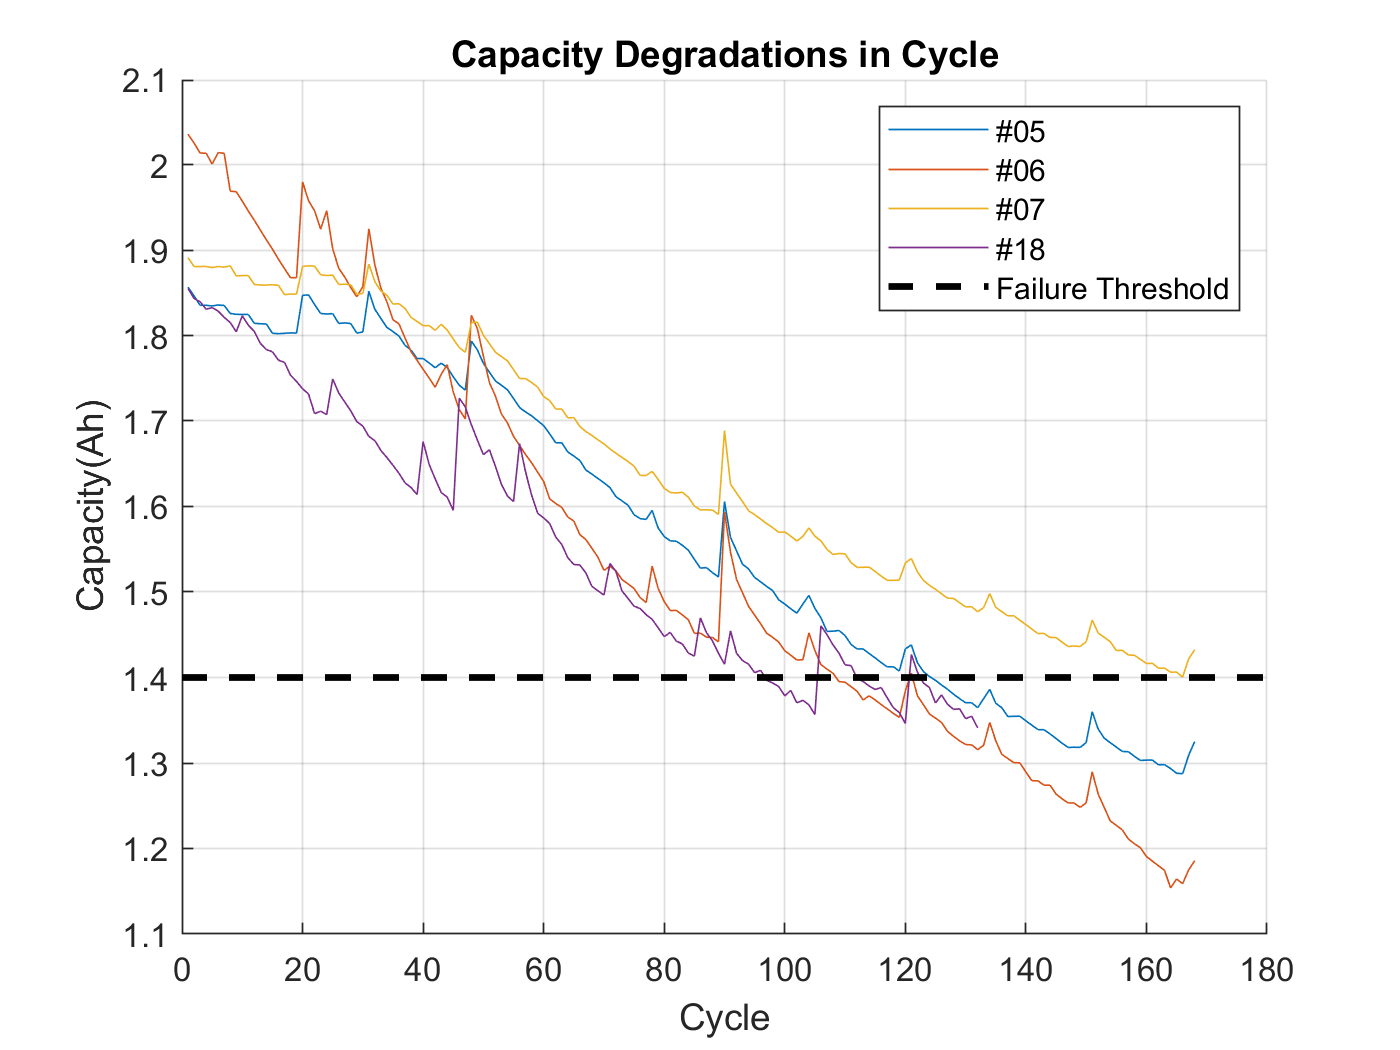

figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(cap05), hold on, plot(cap06), plot(cap07), plot(cap18); plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on, legend( '#05',                '#06',       '#07',       '#18','Failure Threshold')

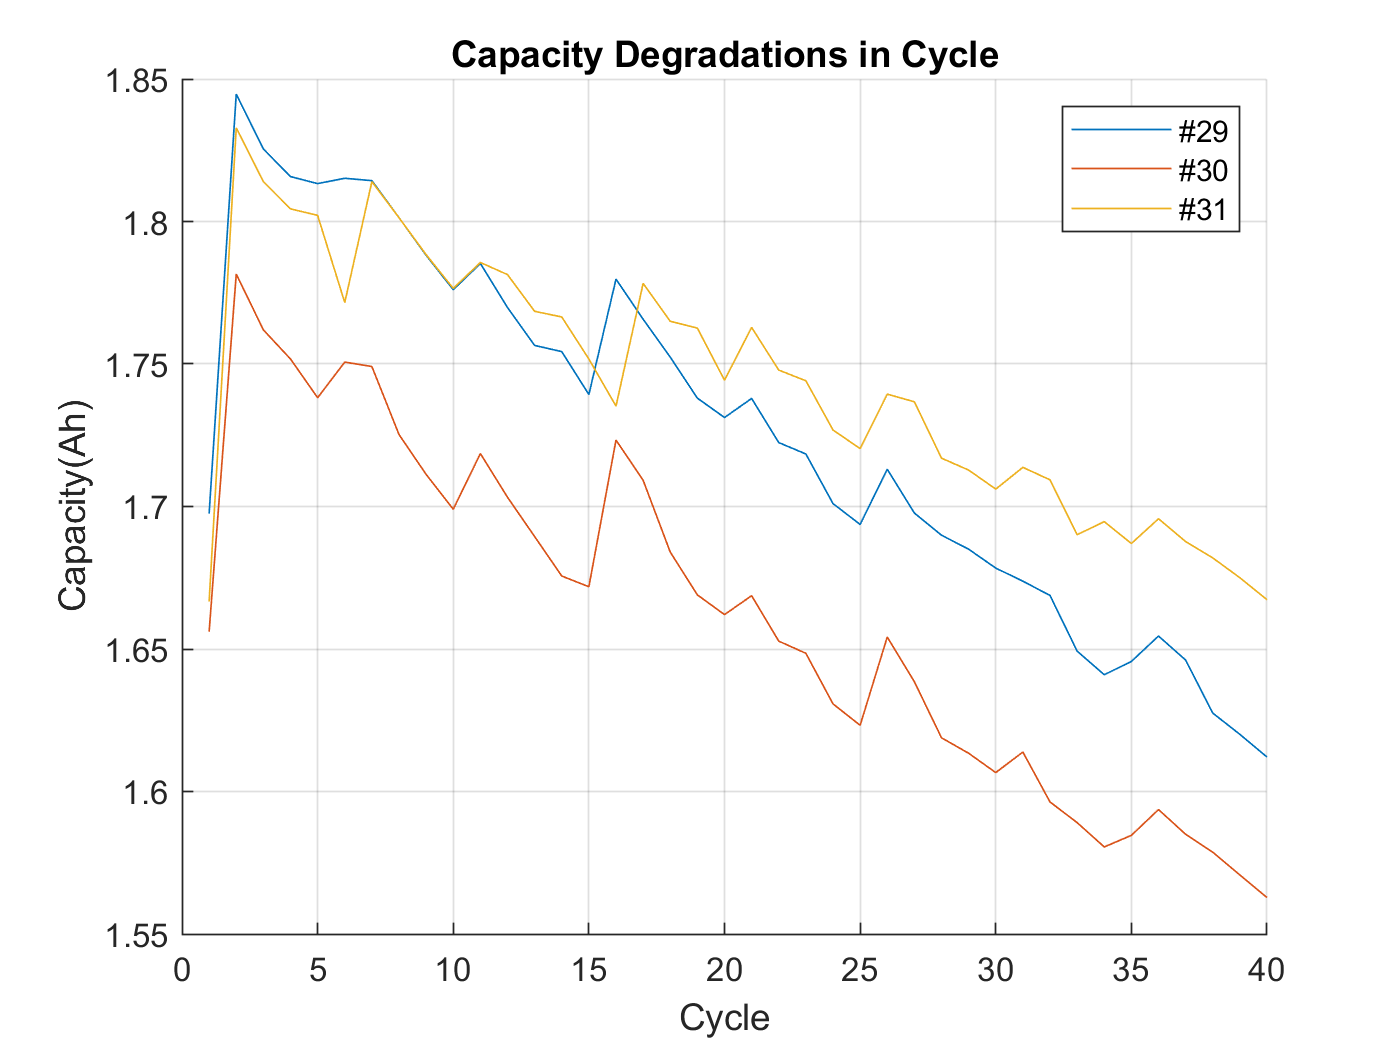


figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(cap29), hold on, plot(cap30), plot(cap31)
hold off, grid on, legend( '#29',                '#30',       '#31')

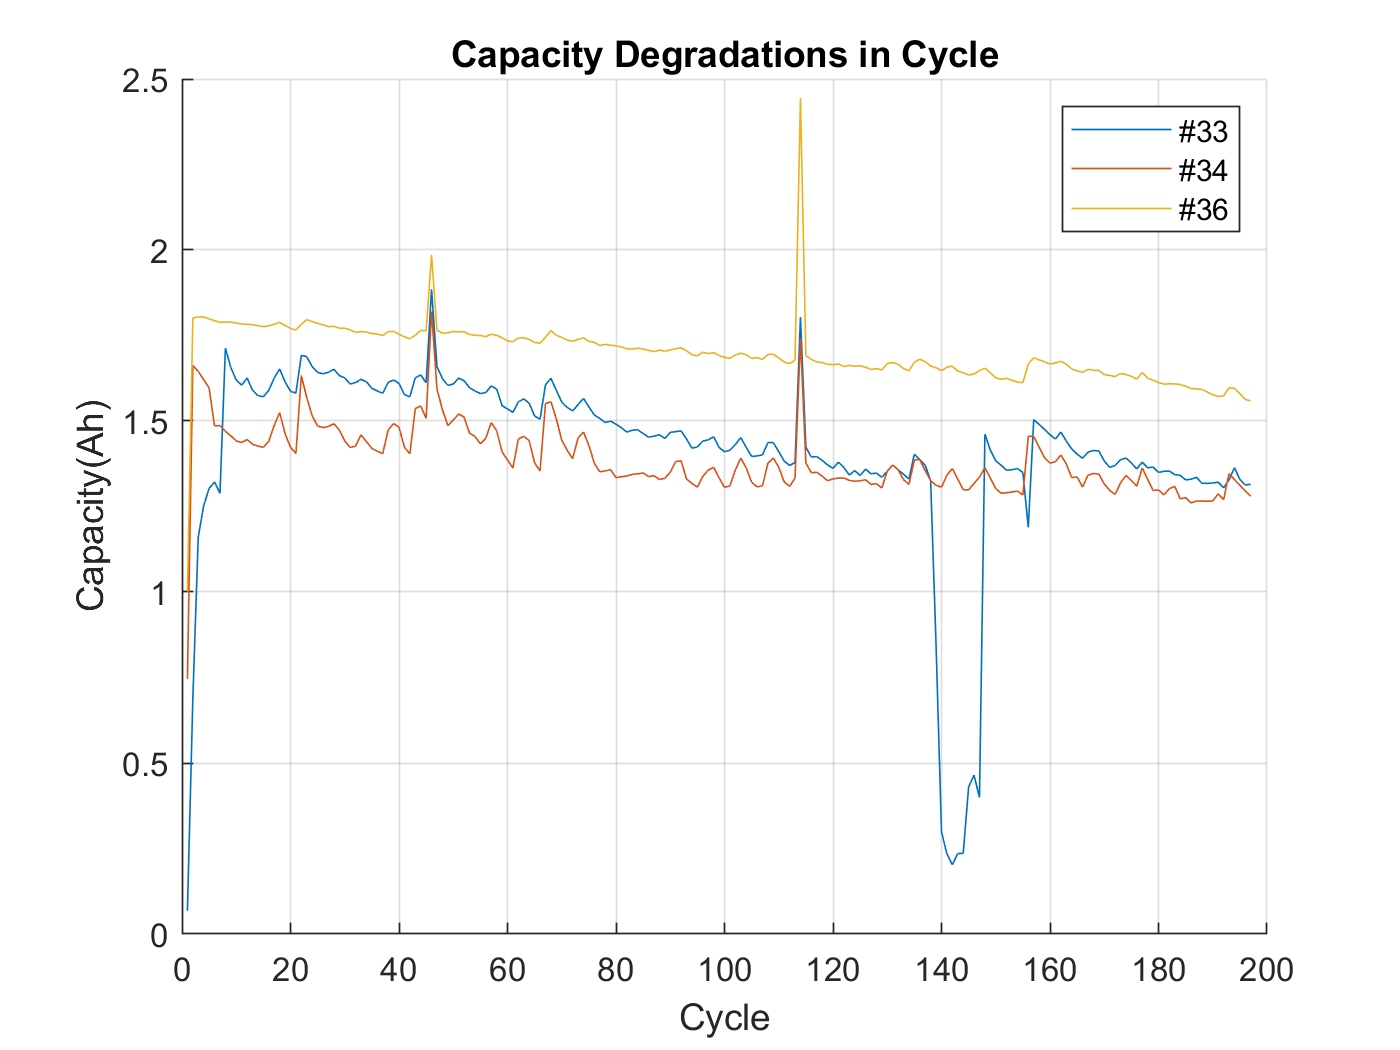


figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(cap33), hold on, plot(cap34), plot(cap36) 
hold off, grid on, legend( '#33',                '#34',       '#36')

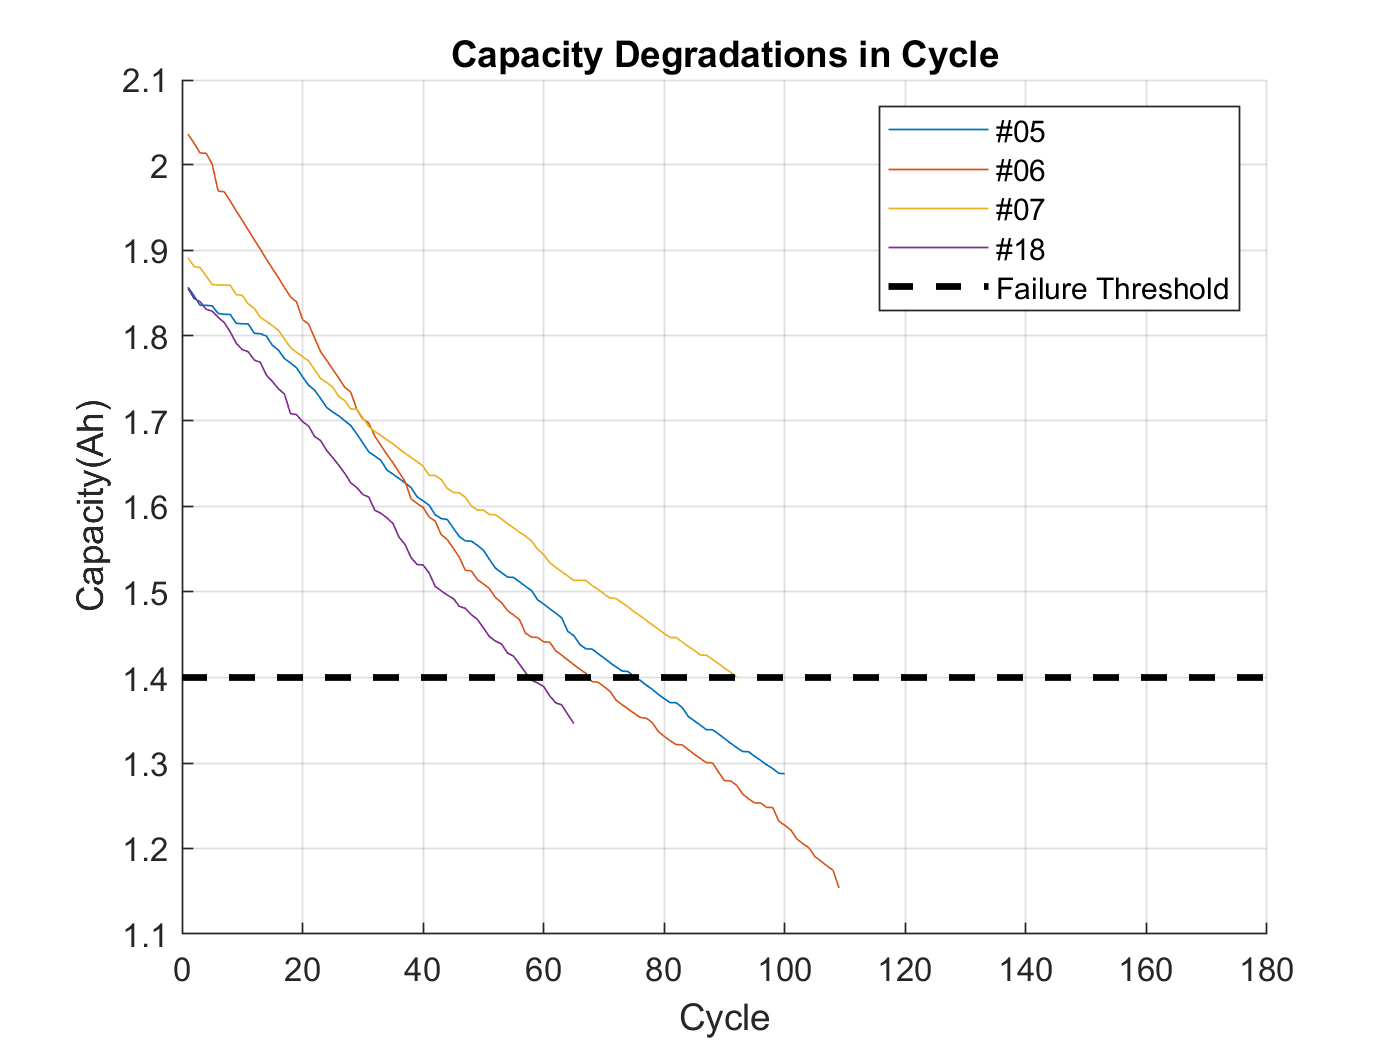

figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacity05), plot(capacity06), plot(capacity07), plot(capacity18); plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on, legend( '#05',                 '#06',            '#07',            '#18','Failure Threshold')

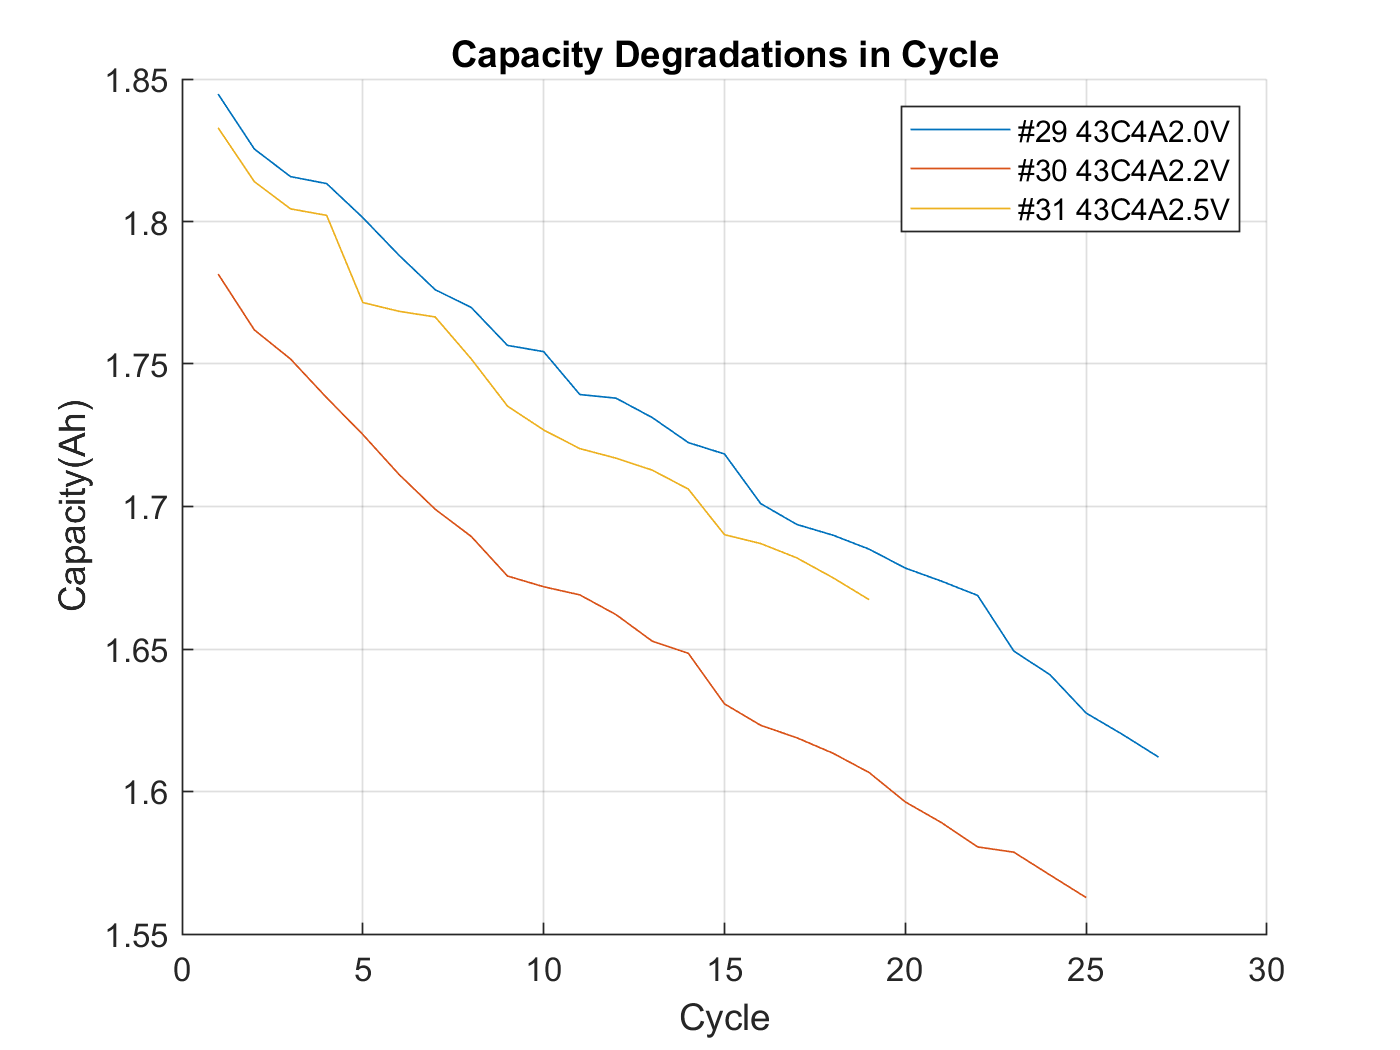


figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacity29), plot(capacity30), plot(capacity31)
hold off, grid on, legend( '#29 43C4A2.0V','#30 43C4A2.2V','#31 43C4A2.5V')

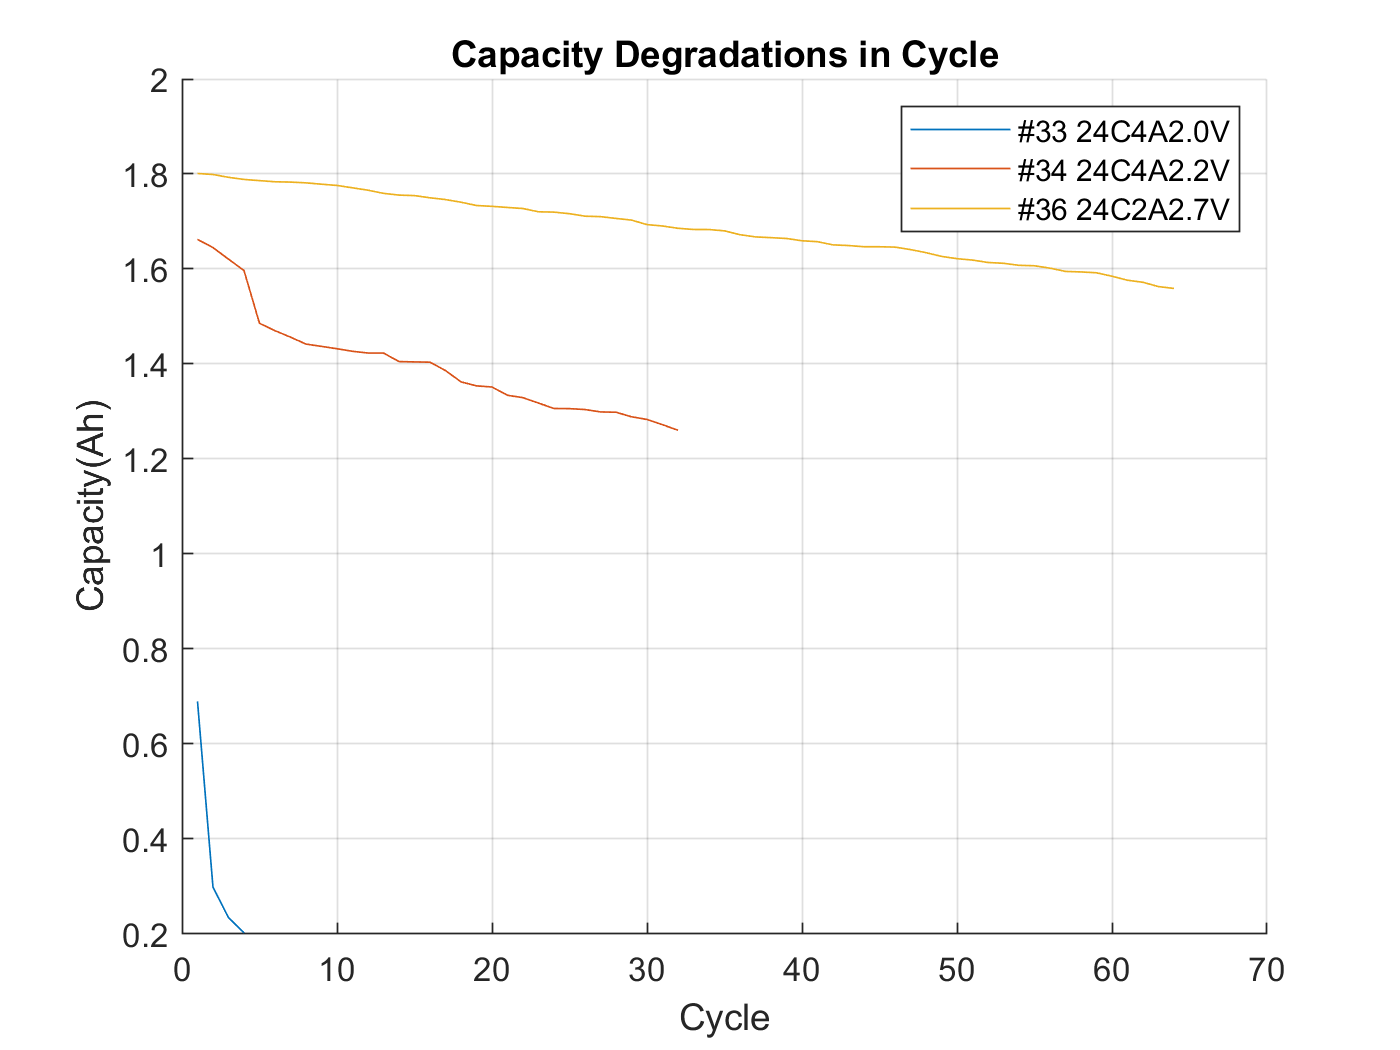


figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacity33), plot(capacity34), plot(capacity36) 
hold off, grid on, legend( '#33 24C4A2.0V','#34 24C4A2.2V','#36 24C2A2.7V')

pattern_temp05 = 24;

pattern_temp06 = 24;

pattern_temp07 = 24;

pattern_temp18 = 24;

pattern_temp29 = 43;

pattern_temp30 = 43;

pattern_temp31 = 43;

pattern_temp32 = 43;

pattern_temp33 = 24;

pattern_temp34 = 24;

pattern_temp36 = 24;

pattern_CC_amps05 = 2;

pattern_CC_amps06 = 2;

pattern_CC_amps07 = 2;

pattern_CC_amps18 = 2;

pattern_CC_amps29 = 4;

pattern_CC_amps30 = 4;

pattern_CC_amps31 = 4;

pattern_CC_amps32 = 4;

pattern_CC_amps33 = 4;

pattern_CC_amps34 = 4;

pattern_CC_amps36 = 2;

pattern_dVolt05 = 4.2 - 2.7 ; 

pattern_dVolt06 = 4.2 - 2.5 ; 

pattern_dVolt07 = 4.2 - 2.2 ; 

pattern_dVolt18 = 4.2 - 2.5 ; 

pattern_dVolt29 = 4.2 - 2.0 ;   

pattern_dVolt30 = 4.2 - 2.2 ;   

pattern_dVolt31 = 4.2 - 2.5 ;   

pattern_dVolt32 = 4.2 - 2.7 ;   

pattern_dVolt33 = 4.2 - 2.0 ; 

pattern_dVolt34 = 4.2 - 2.2 ; 

pattern_dVolt36 = 4.2 - 2.7 ; 

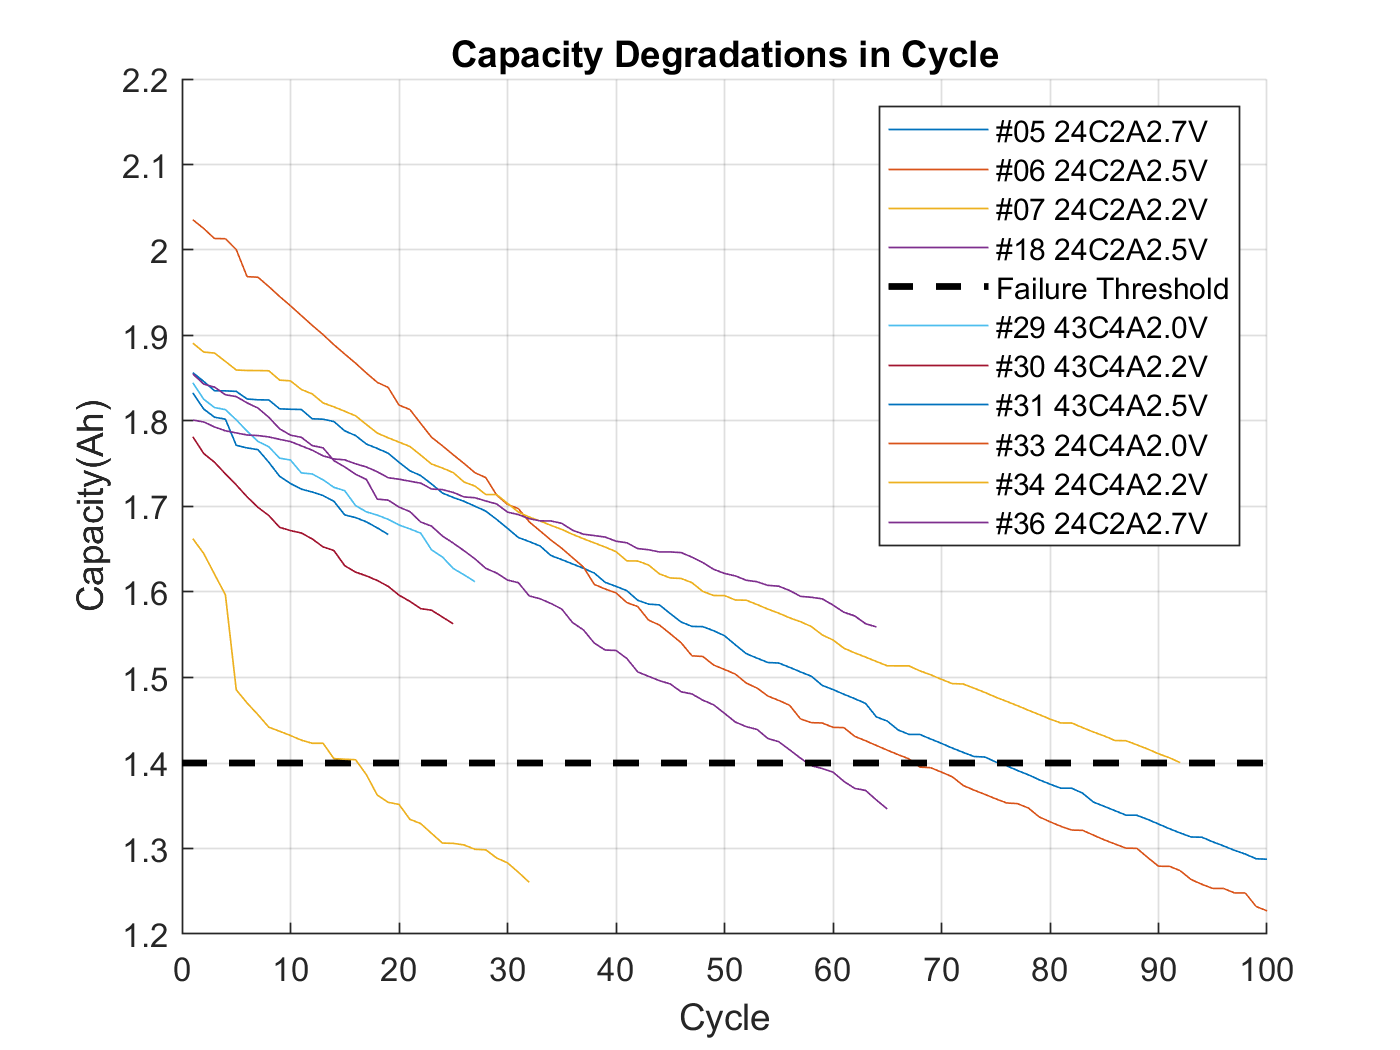

figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacity05), plot(capacity06), plot(capacity07), plot(capacity18); plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2),plot(capacity29), plot(capacity30), plot(capacity31),plot(capacity33), plot(capacity34), plot(capacity36) 
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V', '#07 24C2A2.2V','#18 24C2A2.5V','Failure Threshold','#29 43C4A2.0V','#30 43C4A2.2V','#31 43C4A2.5V','#33 24C4A2.0V','#34 24C4A2.2V','#36 24C2A2.7V')
ylim([1.2 2.2]), xlim([0,100])

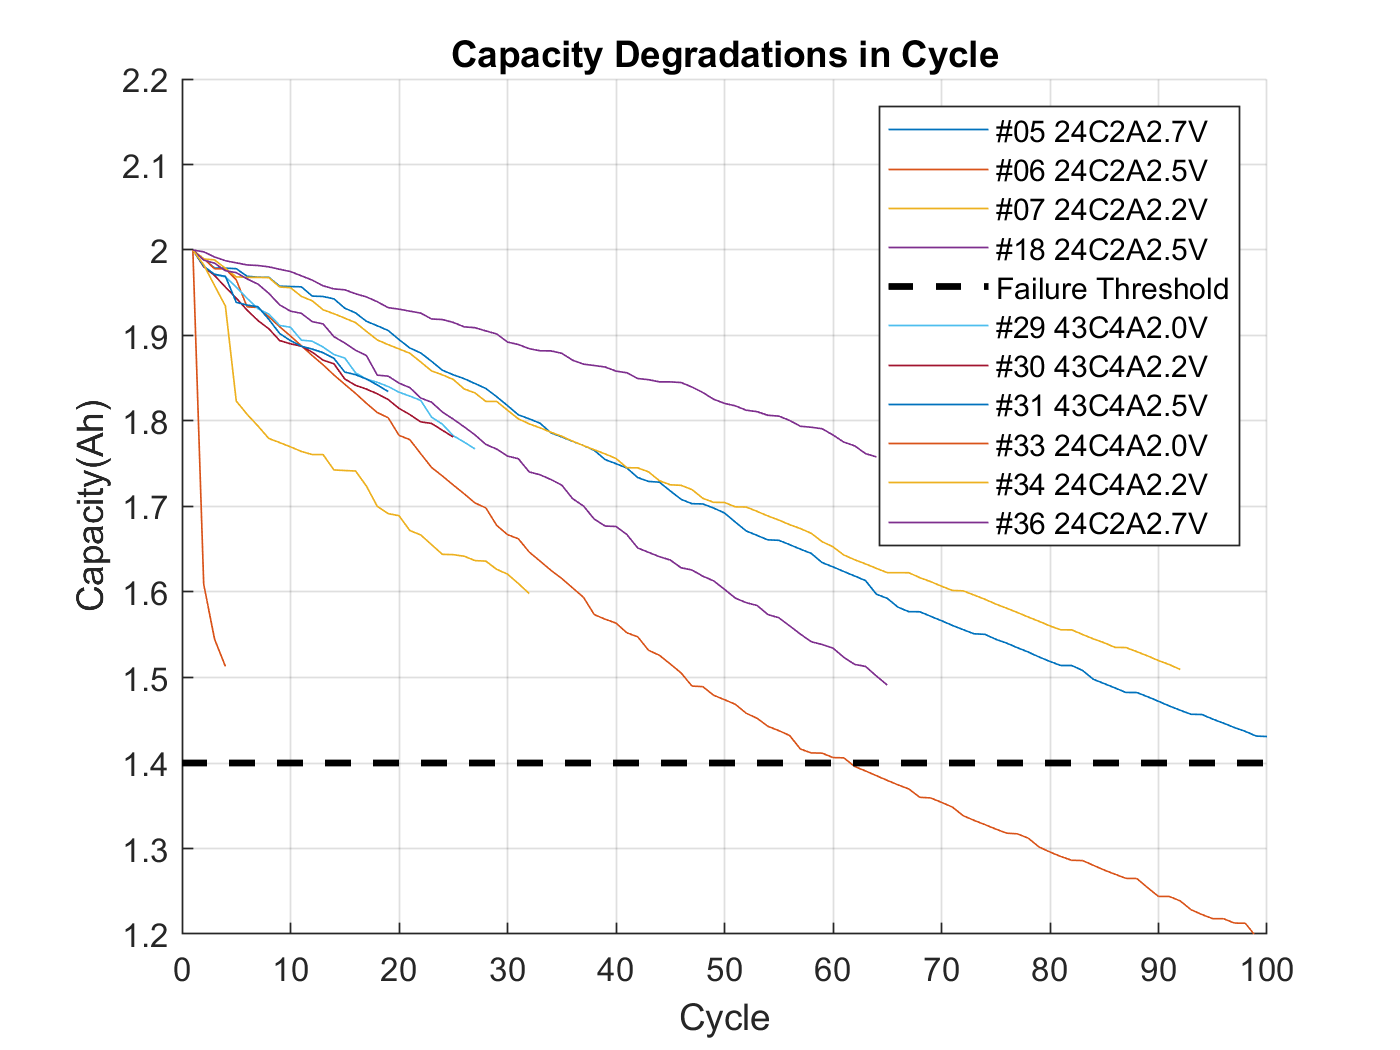

figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacityNorm05), plot(capacityNorm06), plot(capacityNorm07), plot(capacityNorm18); plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2),plot(capacityNorm29), plot(capacityNorm30), plot(capacityNorm31),plot(capacityNorm33), plot(capacityNorm34), plot(capacityNorm36) 
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V', '#07 24C2A2.2V','#18 24C2A2.5V','Failure Threshold','#29 43C4A2.0V','#30 43C4A2.2V','#31 43C4A2.5V','#33 24C4A2.0V','#34 24C4A2.2V','#36 24C2A2.7V')
ylim([1.2 2.2]), xlim([0,100])

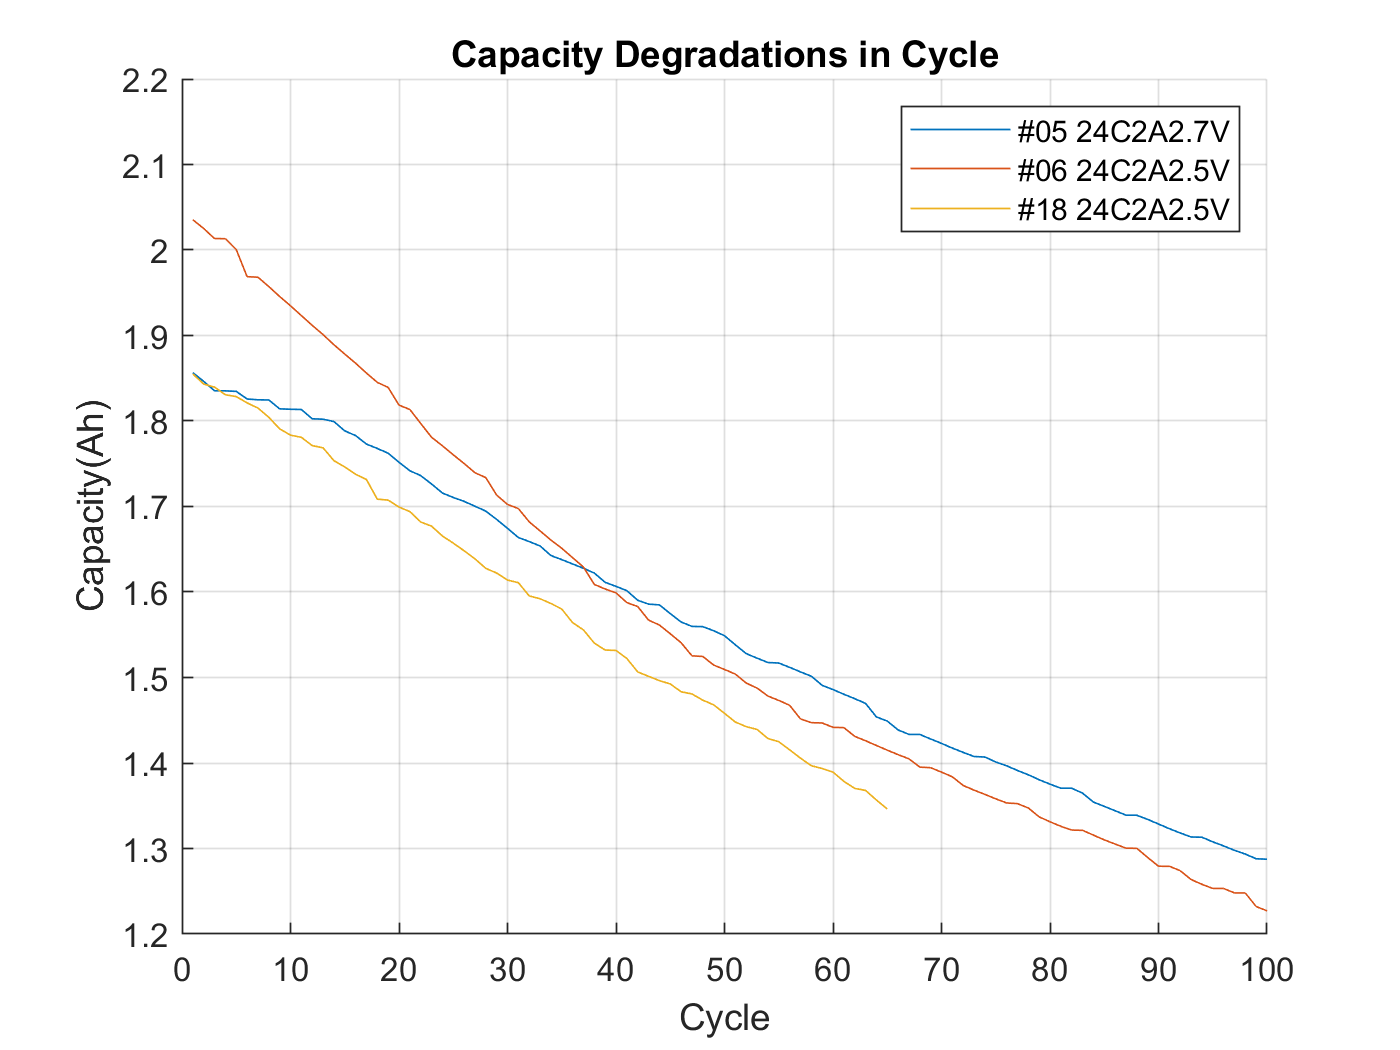


figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacity05), plot(capacity06),plot(capacity18)
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V','#18 24C2A2.5V')
ylim([1.2 2.2]), xlim([0,100])


% no gen
% 27 30
% new data set #01 / #02
result_05(27,1)

ans = 1.7003

result_06(30,1)

ans = 1.7024


% ignore rest time , maxTempDt 
result_05_06 = [ result_05(1:27,:) ; result_06(:,30:end) ];
result_06_05 = [ result_06(1:30,:) ; result_05(:,27:end) ];
result_05_06_all = [ result_05 ; result_06 ];


%{
% gen
% 58 53
% new data set #01 / #02
result_05(58,1)
result_06(53,1)

% ignore rest time , maxTempDt 
result_05_06 = [ result_05(1:58,:) ; result_06(:,53:end) ];
result_06_05 = [ result_06(1:53,:) ; result_05(:,58:end) ];
result_05_06_all = [ result_05 ; result_06 ];
%}

result_all = [ result_05 ; result_06 ; result_07 ; result_18];
result_all_2group = [ result_05 ; result_06 ; result_07 ; result_18;result_34;result_36;];

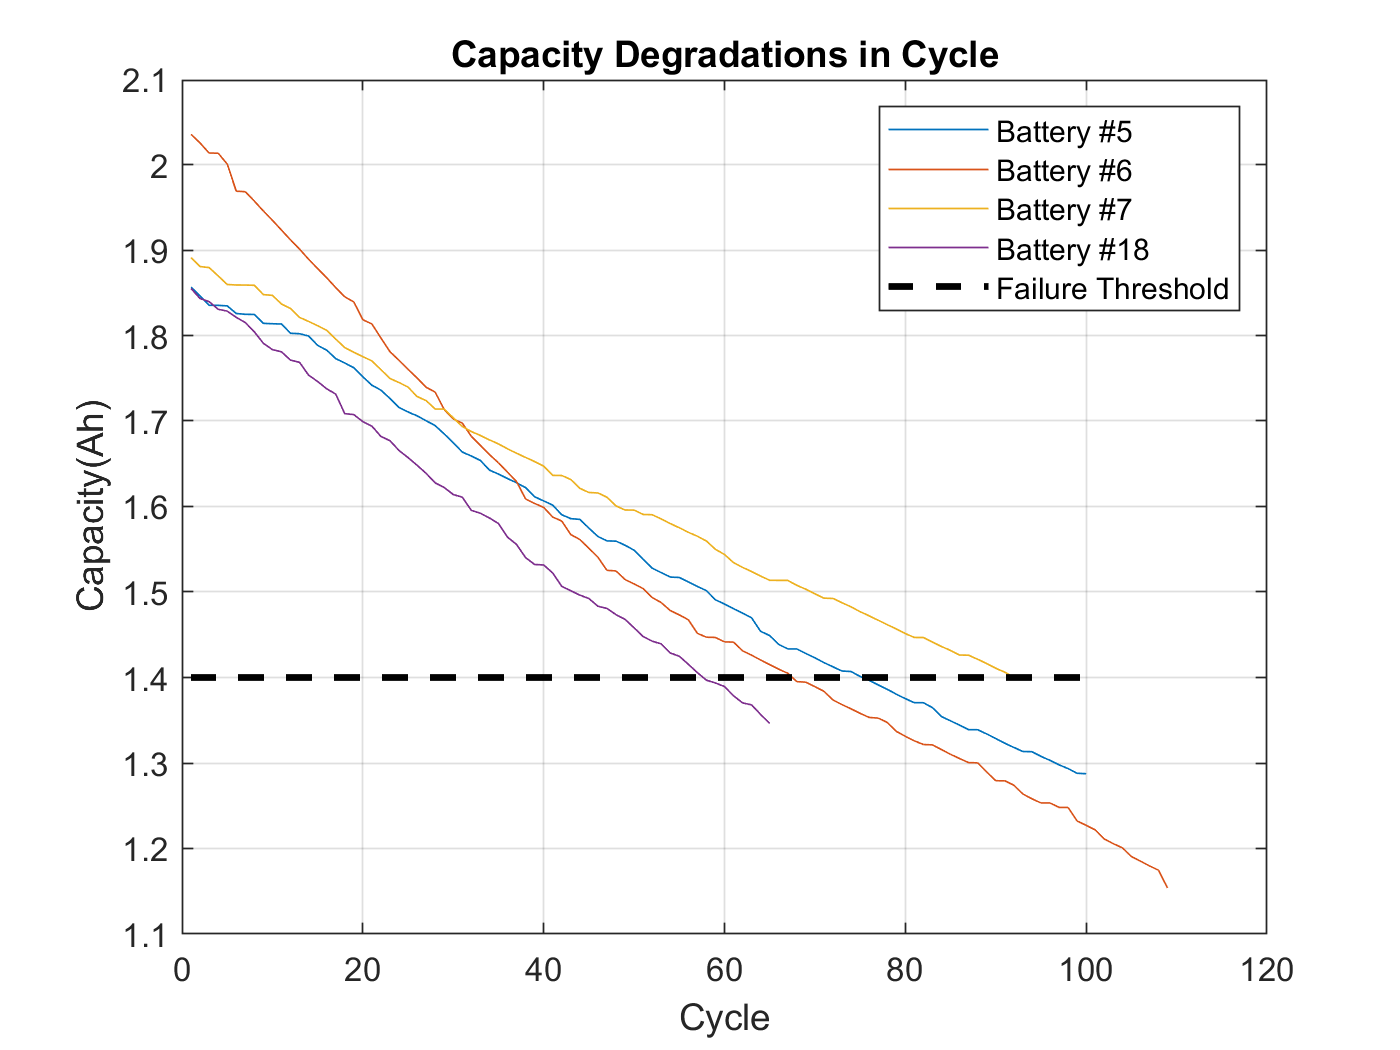


%% org graph - cycle
cycle_number = length(capacity05);

figure
plot(capacity05), hold on, plot(capacity06), plot(capacity07), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle')

%% create vector / table
    
regression_vector_05 = [ ...
    result_05(:, cCcEndTimeSecIdx ) ...
    result_05(:, ohmIdx ) ...
    result_05(:, pattern_dVoltIdx ) ...
    result_05(:, capacityIdx ) ] ;

regression_vector_06 = [ ...
    result_06(:, cCcEndTimeSecIdx ) ...
    result_06(:, ohmIdx ) ...
    result_06(:, pattern_dVoltIdx ) ...
    result_06(:, capacityIdx ) ] ;

regression_vector_07 = [ ...
    result_07(:, cCcEndTimeSecIdx ) ...
    result_07(:, ohmIdx ) ...
    result_07(:, pattern_dVoltIdx ) ...
    result_07(:, capacityIdx ) ] ;

regression_vector_18 = [ ...
    result_18(:, cCcEndTimeSecIdx ) ...
    result_18(:, ohmIdx ) ...
    result_18(:, pattern_dVoltIdx ) ...
    result_18(:, capacityIdx ) ] ;

regression_vector_34 = [ ...
    result_34(:, cCcEndTimeSecIdx ) ...
    result_34(:, ohmIdx ) ...
    result_34(:, pattern_dVoltIdx ) ...
    result_34(:, capacityIdx ) ] ;

regression_vector_36 = [ ...
    result_36(:, cCcEndTimeSecIdx ) ...
    result_36(:, ohmIdx ) ...
    result_36(:, pattern_dVoltIdx ) ...
    result_36(:, capacityIdx ) ] ;

regression_vector_all = [ ...
    result_all(:, cCcEndTimeSecIdx ) ...
    result_all(:, ohmIdx ) ...
    result_all(:, pattern_dVoltIdx ) ...
    result_all(:, capacityIdx ) ] ;

regression_vector_05_06_all = [ ...
    result_05_06_all(:, cCcEndTimeSecIdx ) ...
    result_05_06_all(:, ohmIdx ) ...
    result_05_06_all(:, pattern_dVoltIdx ) ...
    result_05_06_all(:, capacityIdx ) ] ;

regression_vector_05_06 = [ ...
    result_05_06(:, cCcEndTimeSecIdx ) ...
    result_05_06(:, ohmIdx ) ...
    result_05_06(:, pattern_dVoltIdx ) ...
    result_05_06(:, capacityIdx ) ] ;

regression_vector_06_05 = [ ...
    result_06_05(:, cCcEndTimeSecIdx ) ...
    result_06_05(:, ohmIdx ) ...
    result_06_05(:, pattern_dVoltIdx ) ...
    result_06_05(:, capacityIdx ) ] ;

% works
regression_table_05 = array2table(regression_vector_05,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_06 = array2table(regression_vector_06,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_05_06 = array2table(regression_vector_05_06,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_06_05 = array2table(regression_vector_06_05,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_05_06_all = array2table(regression_vector_05_06_all,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_07 = array2table(regression_vector_07,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_18 = array2table(regression_vector_18,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_34 = array2table(regression_vector_34,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});
regression_table_36 = array2table(regression_vector_36,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_all = array2table(regression_vector_all,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});
    
% https://kr.mathworks.com/help/matlab/ref/cell2table.html    
% works
%{
regression_table_5 = array2table(regression_vector_05,...
    'VariableNames',{'cCcEndTimeSec','ohm','capacity'});

regression_table_6 = array2table(regression_vector_06,...
    'VariableNames',{'cCcEndTimeSec','ohm','capacity'});
%}


## corellaton

%{ 
% error after adding pattern_dVolt
figure
[R5,PValue5] = corrplot(regression_vector_05,'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'})
figure
[R6,PValue6] = corrplot(regression_vector_06,'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'})
%}


%% linear regression

% https://kr.mathworks.com/help/stats/fitlm.html
modelspecXU1 = ' capacity ~  cCcEndTimeSec + ohm + pattern_dVolt ';
modelspecX = ' capacity ~  cCcEndTimeSec + ohm ';
modelspecX1U1 = ' capacity ~  cCcEndTimeSec + pattern_dVolt ';

regression_table_all = B5,6,7,8

모든 변수를 사용하고 사용자 패턴을 사용할때 사용자 패턴이 유의미하지 않다.

mdlXU1 = fitlm(regression_table_all,modelspecXU1 )

mdlXU1 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)          1.4102      0.065638     21.485     1.346e-66
    cCcEndTimeSec    0.00018456    1.0721e-05     17.215    5.9963e-49
    ohm                 -108.95        11.317    -9.6278    1.1018e-19
    pattern_dVolt      0.021175      0.024255    0.87302       0.38323


Number of observations: 366, Error degrees of freedom: 362
Root Mean Squared Error: 0.0829
R-squared: 0.819,  Adjusted R-Squared: 0.817
F-statistic vs. constant model: 546, p-value = 6.53e-134

% 모든 변수를 사용하고 사용자 패턴을 사용하지 않을 경우 모든 변수는 유의미하다.

mdlX = fitlm(regression_table_all,modelspecX )

mdlX = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)          1.4396      0.056342     25.551    3.9888e-83
    cCcEndTimeSec    0.00018625    1.0541e-05     17.669    7.4173e-51
    ohm                 -107.98        11.258    -9.5916    1.4406e-19


Number of observations: 366, Error degrees of freedom: 363
Root Mean Squared Error: 0.0829
R-squared: 0.819,  Adjusted R-Squared: 0.818
F-statistic vs. constant model: 819, p-value = 2.95e-135

% 주요 변수 하나를 사용하고 사용자 패턴을 사용하는 경우 사용자패턴은 유의미하지 않는다.

mdlX1U1 = fitlm(regression_table_all,modelspecX1U1 )

mdlX1U1 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE          tStat        pValue   
                     __________    __________    _________    ___________

    (Intercept)         0.92747      0.047406       19.564     1.0282e-58
    cCcEndTimeSec    0.00026423    7.6274e-06       34.643    3.9106e-117
    pattern_dVolt    -0.0018406      0.027014    -0.068135        0.94572


Number of observations: 366, Error degrees of freedom: 363
Root Mean Squared Error: 0.0928
R-squared: 0.773,  Adjusted R-Squared: 0.771
F-statistic vs. constant model: 616, p-value = 1.88e-117

배터리 5에서는 모든 변수를 사용하고 사용자 패턴을 사용할때 사용자 패턴이 유의미하다.

modelspecXU1_05 = fitlm(regression_table_05,modelspecXU1 )

modelspecXU1_05 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)               0             0       NaN           NaN
    cCcEndTimeSec    0.00018149    1.6757e-05    10.831    2.4724e-18
    ohm                 -138.13        17.821    -7.751    9.5253e-12
    pattern_dVolt        1.0123      0.058298    17.364    2.2339e-31


Number of observations: 100, Error degrees of freedom: 97
Root Mean Squared Error: 0.0646
R-squared: 0.867,  Adjusted R-Squared: 0.865
F-statistic vs. constant model: 317, p-value = 2.85e-43

배터리 6에서는 모든 변수를 사용하고 사용자 패턴을 사용할때 사용자 패턴이 유의미하다.

modelspecXU1_06 = fitlm(regression_table_06,modelspecXU1 )

modelspecXU1_06 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate        SE        tStat       pValue  
                     __________    ________    _______    __________

    (Intercept)               0           0        NaN           NaN
    cCcEndTimeSec    0.00014023    1.63e-05     8.6032    8.1714e-14
    ohm                 -167.66      16.212    -10.342    1.0476e-17
    pattern_dVolt        1.0489    0.051014     20.562      1.32e-38


Number of observations: 109, Error degrees of freedom: 106
Root Mean Squared Error: 0.0624
R-squared: 0.939,  Adjusted R-Squared: 0.938
F-statistic vs. constant model: 812, p-value = 5.3e-65

배터리 6에서는 모든 변수를 사용하고 사용자 패턴을 사용할때 사용자 패턴이 유의미하다.

modelspecXU1_07 = fitlm(regression_table_07,modelspecXU1 )

modelspecXU1_07 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    cCcEndTimeSec    0.00016415    1.6991e-05     9.6608    1.7891e-15
    ohm                  -171.2        18.621    -9.1941    1.6353e-14
    pattern_dVolt       0.83708      0.044073     18.993    6.9924e-33


Number of observations: 92, Error degrees of freedom: 89
Root Mean Squared Error: 0.0626
R-squared: 0.819,  Adjusted R-Squared: 0.815
F-statistic vs. constant model: 201, p-value = 9.73e-34

배터리 18에서는 모든 변수를 사용하고 사용자 패턴을 사용할때 사용자 패턴이 유의미하다.

modelspecXU1_18 = fitlm(regression_table_18,modelspecXU1 )

modelspecXU1_18 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    cCcEndTimeSec    0.00022135    2.0525e-05     10.785    9.1623e-16
    ohm                  803.36         104.8     7.6656    1.6565e-10
    pattern_dVolt      -0.68357       0.16702    -4.0926     0.0001273


Number of observations: 65, Error degrees of freedom: 62
Root Mean Squared Error: 0.076
R-squared: 0.76,  Adjusted R-Squared: 0.752
F-statistic vs. constant model: 98, p-value = 6.4e-20

%modelspecXU1_33 = fitlm(regression_table_33,modelspecXU1 )

배터리 34에서는 모든 변수를 사용하고 사용자 패턴을 사용할때 사용자 패턴이 유의미하다.

modelspecXU1_34 = fitlm(regression_table_34,modelspecXU1 )

modelspecXU1_34 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat      pValue  
                     __________    __________    _______    _________

    (Intercept)               0             0        NaN          NaN
    cCcEndTimeSec    0.00067882    0.00011658      5.823     2.95e-06
    ohm                 -77.799        38.588    -2.0162     0.053469
    pattern_dVolt       0.28749      0.033069     8.6935    1.924e-09


Number of observations: 32, Error degrees of freedom: 29
Root Mean Squared Error: 0.0251
R-squared: 0.95,  Adjusted R-Squared: 0.947
F-statistic vs. constant model: 278, p-value = 1.19e-19

배터리 36에서는 모든 변수를 사용하고 사용자 패턴을 사용할때 사용자 패턴이 유의미하다.

modelspecXU1_36 = fitlm(regression_table_36,modelspecXU1 )

modelspecXU1_36 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)               0             0       NaN           NaN
    cCcEndTimeSec    0.00026337    1.1409e-05    23.084     1.546e-31
    ohm                  86.748        5.1659    16.793     2.375e-24
    pattern_dVolt       0.48898      0.011159     43.82    2.8894e-47


Number of observations: 64, Error degrees of freedom: 61
Root Mean Squared Error: 0.00749
R-squared: 0.989,  Adjusted R-Squared: 0.988
F-statistic vs. constant model: 2.69e+03, p-value = 3.46e-60


mdlX1U1_05 = fitlm(regression_table_05,modelspecX1U1 )

mdlX1U1_05 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)               0             0       NaN           NaN
    cCcEndTimeSec    0.00027586    1.4577e-05    18.925    2.4892e-34
    pattern_dVolt       0.58586      0.024419    23.992    1.4206e-42


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 0.0818
R-squared: 0.785,  Adjusted R-Squared: 0.783
F-statistic vs. constant model: 358, p-value = 1.7e-34

modelspecX_05 = fitlm(regression_table_05,modelspecX )

modelspecX_05 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)          1.5184      0.087448    17.364    1.6003e-31
    cCcEndTimeSec    0.00018149    1.6757e-05    10.831    2.1791e-18
    ohm                 -138.13        17.821    -7.751    9.0416e-12


Number of observations: 100, Error degrees of freedom: 97
Root Mean Squared Error: 0.0646
R-squared: 0.867,  Adjusted R-Squared: 0.865
F-statistic vs. constant model: 317, p-value = 2.85e-43

mdlX_05 = fitlm(regression_table_05,modelspecX )

mdlX_05 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)          1.5184      0.087448    17.364    1.6003e-31
    cCcEndTimeSec    0.00018149    1.6757e-05    10.831    2.1791e-18
    ohm                 -138.13        17.821    -7.751    9.0416e-12


Number of observations: 100, Error degrees of freedom: 97
Root Mean Squared Error: 0.0646
R-squared: 0.867,  Adjusted R-Squared: 0.865
F-statistic vs. constant model: 317, p-value = 2.85e-43

배터리 6에서는 모든 변수를 사용하고 사용자 패턴을 사용할때 사용자 패턴이 유의미하다.

modelspecXU1_06 = fitlm(regression_table_06,modelspecXU1 )

modelspecXU1_06 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate        SE        tStat       pValue  
                     __________    ________    _______    __________

    (Intercept)               0           0        NaN           NaN
    cCcEndTimeSec    0.00014023    1.63e-05     8.6032    8.1714e-14
    ohm                 -167.66      16.212    -10.342    1.0476e-17
    pattern_dVolt        1.0489    0.051014     20.562      1.32e-38


Number of observations: 109, Error degrees of freedom: 106
Root Mean Squared Error: 0.0624
R-squared: 0.939,  Adjusted R-Squared: 0.938
F-statistic vs. constant model: 812, p-value = 5.3e-65

mdlX1U1_06 = fitlm(regression_table_06,modelspecX1U1 )

mdlX1U1_06 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate        SE        tStat       pValue  
                     __________    _________    ______    __________

    (Intercept)               0            0       NaN           NaN
    cCcEndTimeSec    0.00029016    1.051e-05    27.609    3.2234e-50
    pattern_dVolt       0.53179     0.014231    37.369    7.4947e-63


Number of observations: 109, Error degrees of freedom: 107
Root Mean Squared Error: 0.088
R-squared: 0.877,  Adjusted R-Squared: 0.876
F-statistic vs. constant model: 762, p-value = 1.74e-50

mdl5_6 = fitlm(regression_table_05_06,modelspecXU1 )

mdl5_6 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate          SE         tStat        pValue  
                     ___________    __________    ________    __________

    (Intercept)                0             0         NaN           NaN
    cCcEndTimeSec    -8.8526e-06    1.0525e-05    -0.84107       0.40897
    ohm                  -66.311        8.5423     -7.7626    7.1632e-08
    pattern_dVolt           1.31      0.027074      48.387    1.2037e-24


Number of observations: 27, Error degrees of freedom: 24
Root Mean Squared Error: 0.0262
R-squared: 0.715,  Adjusted R-Squared: 0.692
F-statistic vs. constant model: 30.1, p-value = 2.84e-07

mdl6_5 = fitlm(regression_table_06_05,modelspecXU1 )

mdl6_5 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate          SE         tStat        pValue  
                     ___________    __________    ________    __________

    (Intercept)                0             0         NaN           NaN
    cCcEndTimeSec    -1.3343e-05    2.0131e-05    -0.66281       0.51329
    ohm                   -134.1        16.011     -8.3758    7.4004e-09
    pattern_dVolt         1.3002      0.050142       25.93    4.1648e-20


Number of observations: 30, Error degrees of freedom: 27
Root Mean Squared Error: 0.0532
R-squared: 0.744,  Adjusted R-Squared: 0.725
F-statistic vs. constant model: 39.1, p-value = 1.05e-08

mdl_05_06 = fitlm(regression_table_05_06_all,modelspecXU1 )

mdl_05_06 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)          1.0345      0.090875    11.384    1.3796e-23
    cCcEndTimeSec    0.00016065    1.1666e-05    13.771     5.595e-31
    ohm                  -150.9        11.835    -12.75    8.4727e-28
    pattern_dVolt       0.38181      0.045537    8.3847    8.1298e-15


Number of observations: 209, Error degrees of freedom: 205
Root Mean Squared Error: 0.0637
R-squared: 0.915,  Adjusted R-Squared: 0.914
F-statistic vs. constant model: 740, p-value = 1.22e-109


modelspecXU1_07 = fitlm(regression_table_07,modelspecXU1 )

modelspecXU1_07 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    cCcEndTimeSec    0.00016415    1.6991e-05     9.6608    1.7891e-15
    ohm                  -171.2        18.621    -9.1941    1.6353e-14
    pattern_dVolt       0.83708      0.044073     18.993    6.9924e-33


Number of observations: 92, Error degrees of freedom: 89
Root Mean Squared Error: 0.0626
R-squared: 0.819,  Adjusted R-Squared: 0.815
F-statistic vs. constant model: 201, p-value = 9.73e-34

mdlX1U1_07 = fitlm(regression_table_07,modelspecX1U1 )

mdlX1U1_07 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate        SE        tStat       pValue  
                     __________    _________    ______    __________

    (Intercept)               0            0       NaN           NaN
    cCcEndTimeSec    0.00025131    1.958e-05    12.835    5.8894e-22
    pattern_dVolt       0.47307     0.026889    17.593    1.0166e-30


Number of observations: 92, Error degrees of freedom: 90
Root Mean Squared Error: 0.0869
R-squared: 0.647,  Adjusted R-Squared: 0.643
F-statistic vs. constant model: 165, p-value = 4.81e-22


modelspecXU1_18 = fitlm(regression_table_18,modelspecXU1 )

modelspecXU1_18 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    cCcEndTimeSec    0.00022135    2.0525e-05     10.785    9.1623e-16
    ohm                  803.36         104.8     7.6656    1.6565e-10
    pattern_dVolt      -0.68357       0.16702    -4.0926     0.0001273


Number of observations: 65, Error degrees of freedom: 62
Root Mean Squared Error: 0.076
R-squared: 0.76,  Adjusted R-Squared: 0.752
F-statistic vs. constant model: 98, p-value = 6.4e-20

mdlX1U1_18 = fitlm(regression_table_18,modelspecX1U1 )

mdlX1U1_18 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                     Estimate         SE        tStat       pValue  
                     _________    __________    ______    __________

    (Intercept)              0             0       NaN           NaN
    cCcEndTimeSec    0.0002389    2.8239e-05    8.4601    6.3197e-12
    pattern_dVolt      0.57356      0.043831    13.086    1.7027e-19


Number of observations: 65, Error degrees of freedom: 63
Root Mean Squared Error: 0.105
R-squared: 0.532,  Adjusted R-Squared: 0.524
F-statistic vs. constant model: 71.6, p-value = 5.61e-12




%% get  hat 
% https://kr.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html

capacityHat = predict(mdlXU1,regression_table_05(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacityX1U1Hat = predict(mdlX1U1,regression_table_05(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat05 = predict(modelspecXU1_05,regression_table_05(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacityX1U1Hat5 = predict(mdlX1U1_05,regression_table_05(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat06 = predict(modelspecXU1_06,regression_table_06(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacityX1U1Hat6 = predict(mdlX1U1_06,regression_table_06(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat07 = predict(modelspecXU1_07,regression_table_07(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacityX1U1Hat7 = predict(mdlX1U1_07,regression_table_07(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat18 = predict(modelspecXU1_18,regression_table_18(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacityX1U1Hat18 = predict(mdlX1U1_18,regression_table_18(:,{'cCcEndTimeSec','pattern_dVolt'}))';

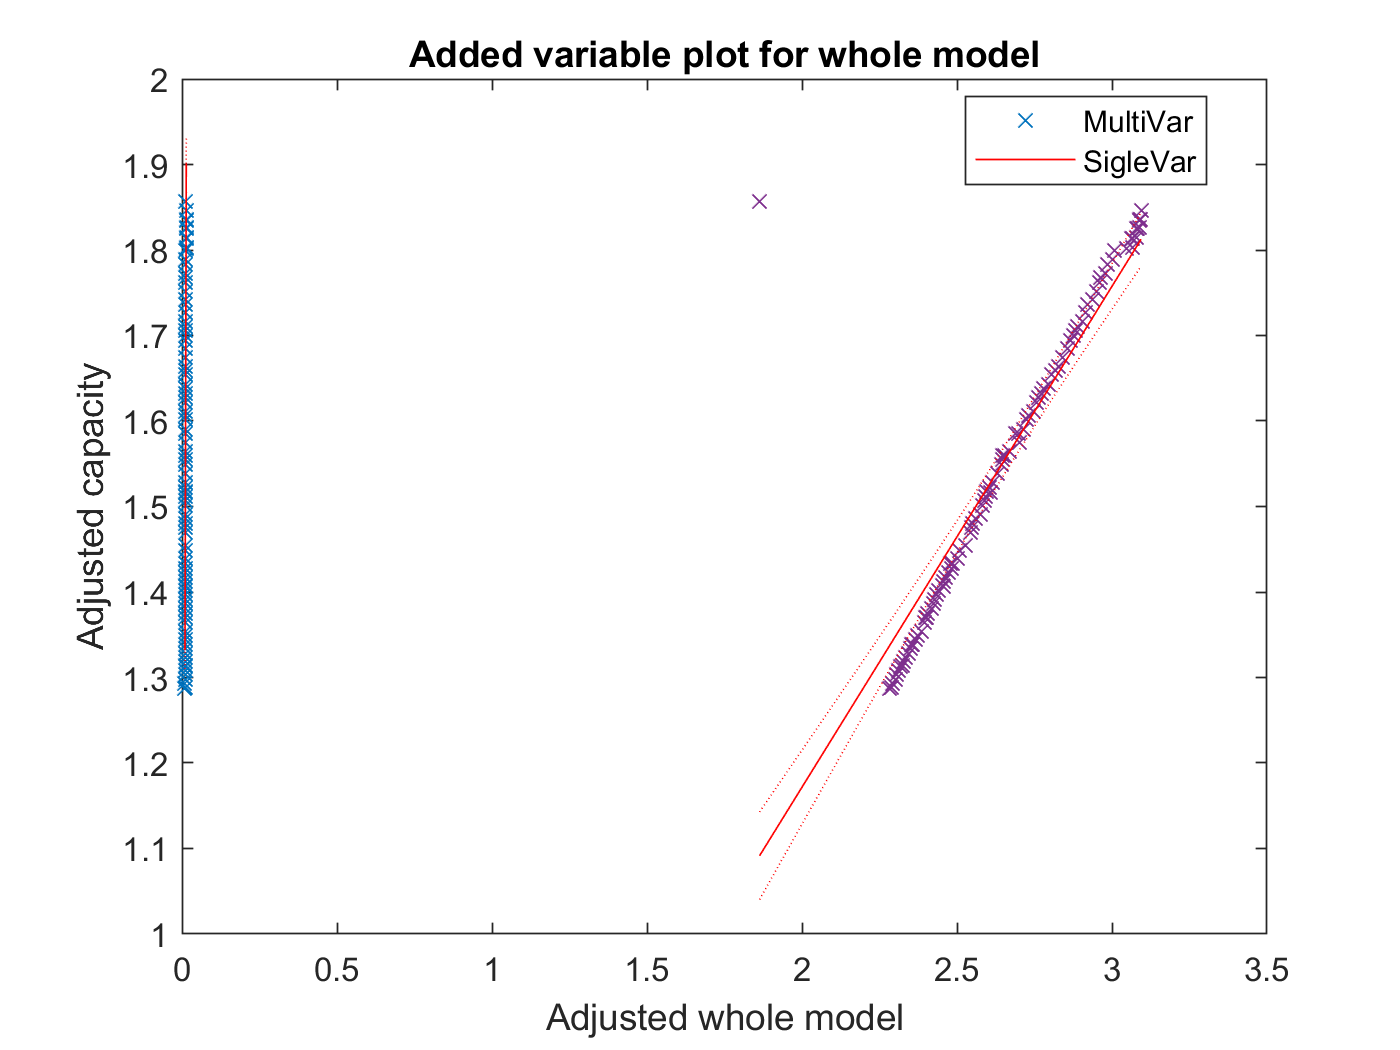


%% plot - model
figure
plot(modelspecXU1_05)
hold on 
plot(mdlX1U1_05)
hold off
legend('MultiVar','SigleVar')

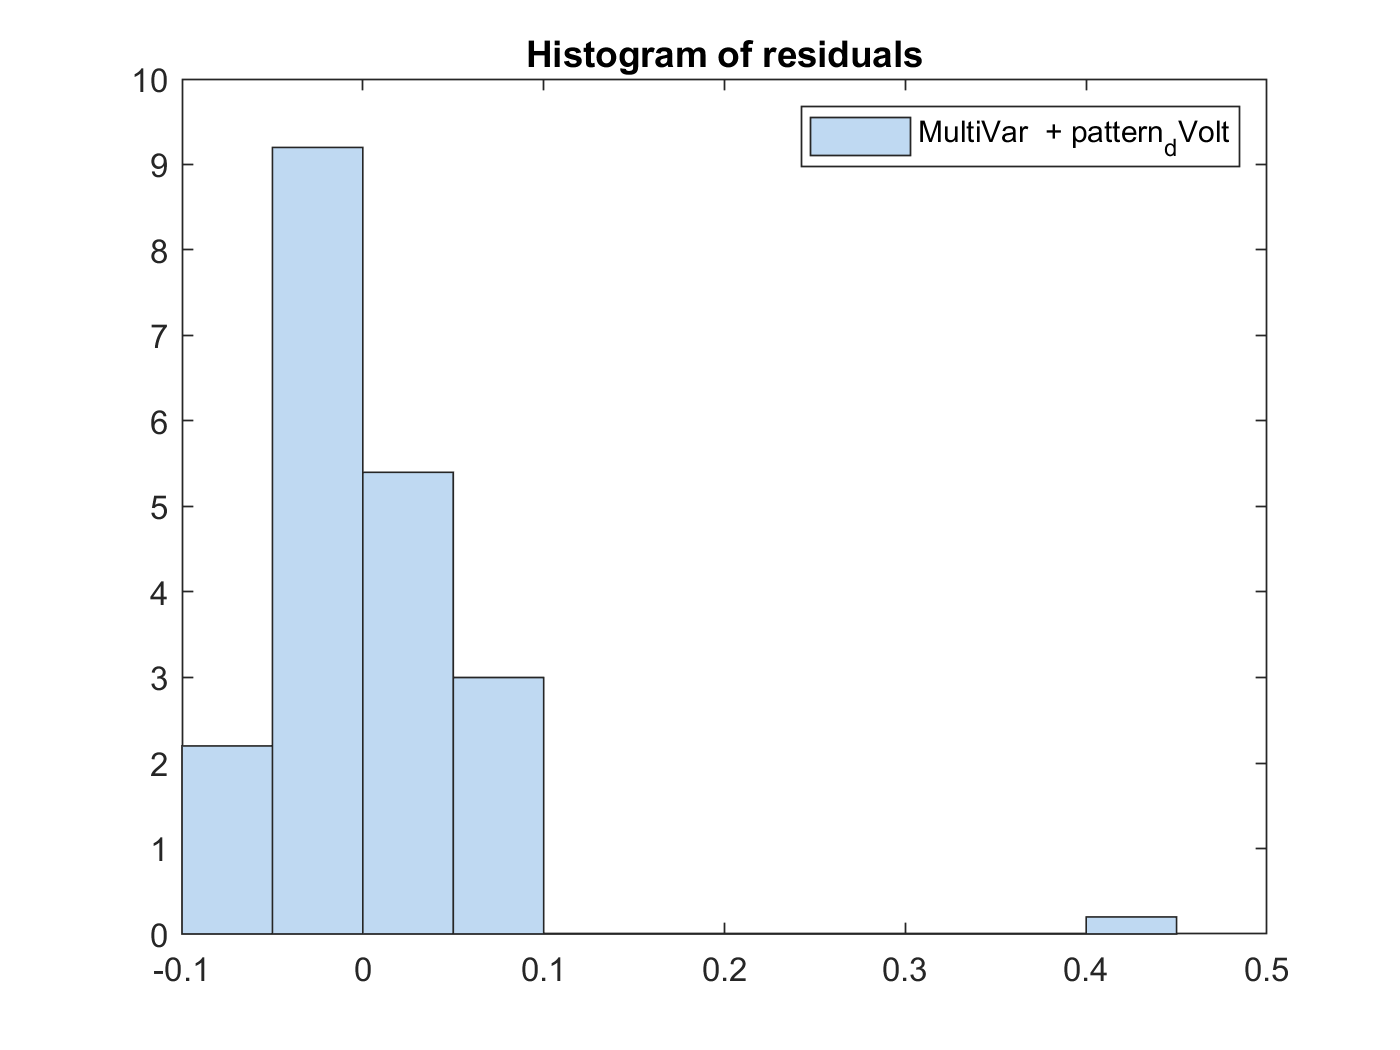



%% plot - residuals 
plotResiduals(modelspecXU1_05)
legend('MultiVar  + pattern_dVolt')

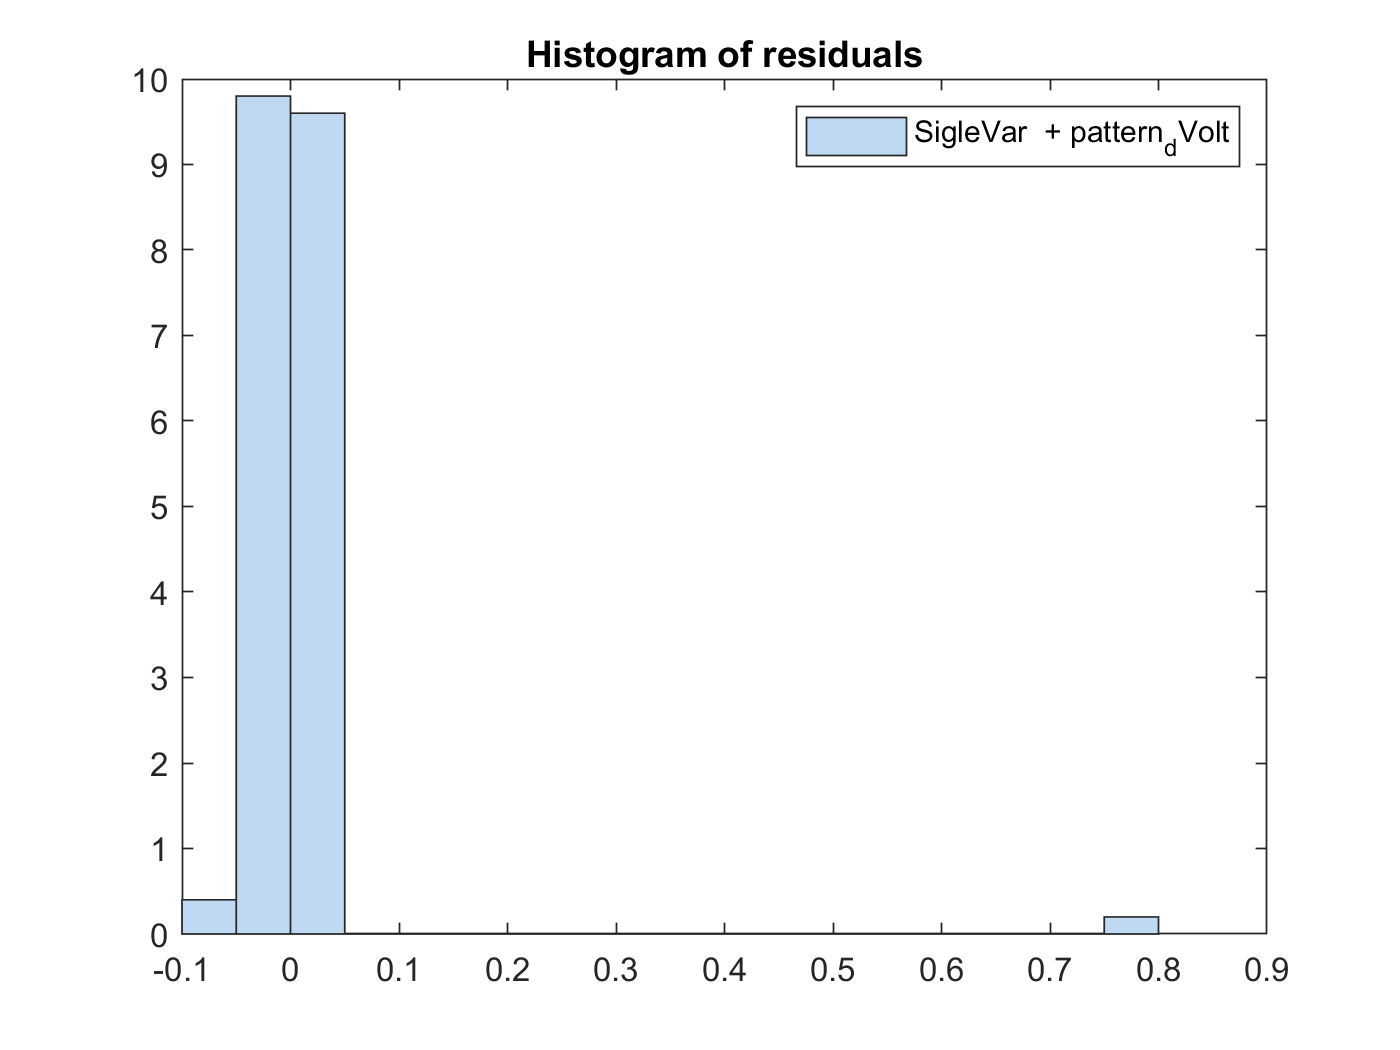

figure
plotResiduals(mdlX1U1_05)
legend('SigleVar  + pattern_dVolt')

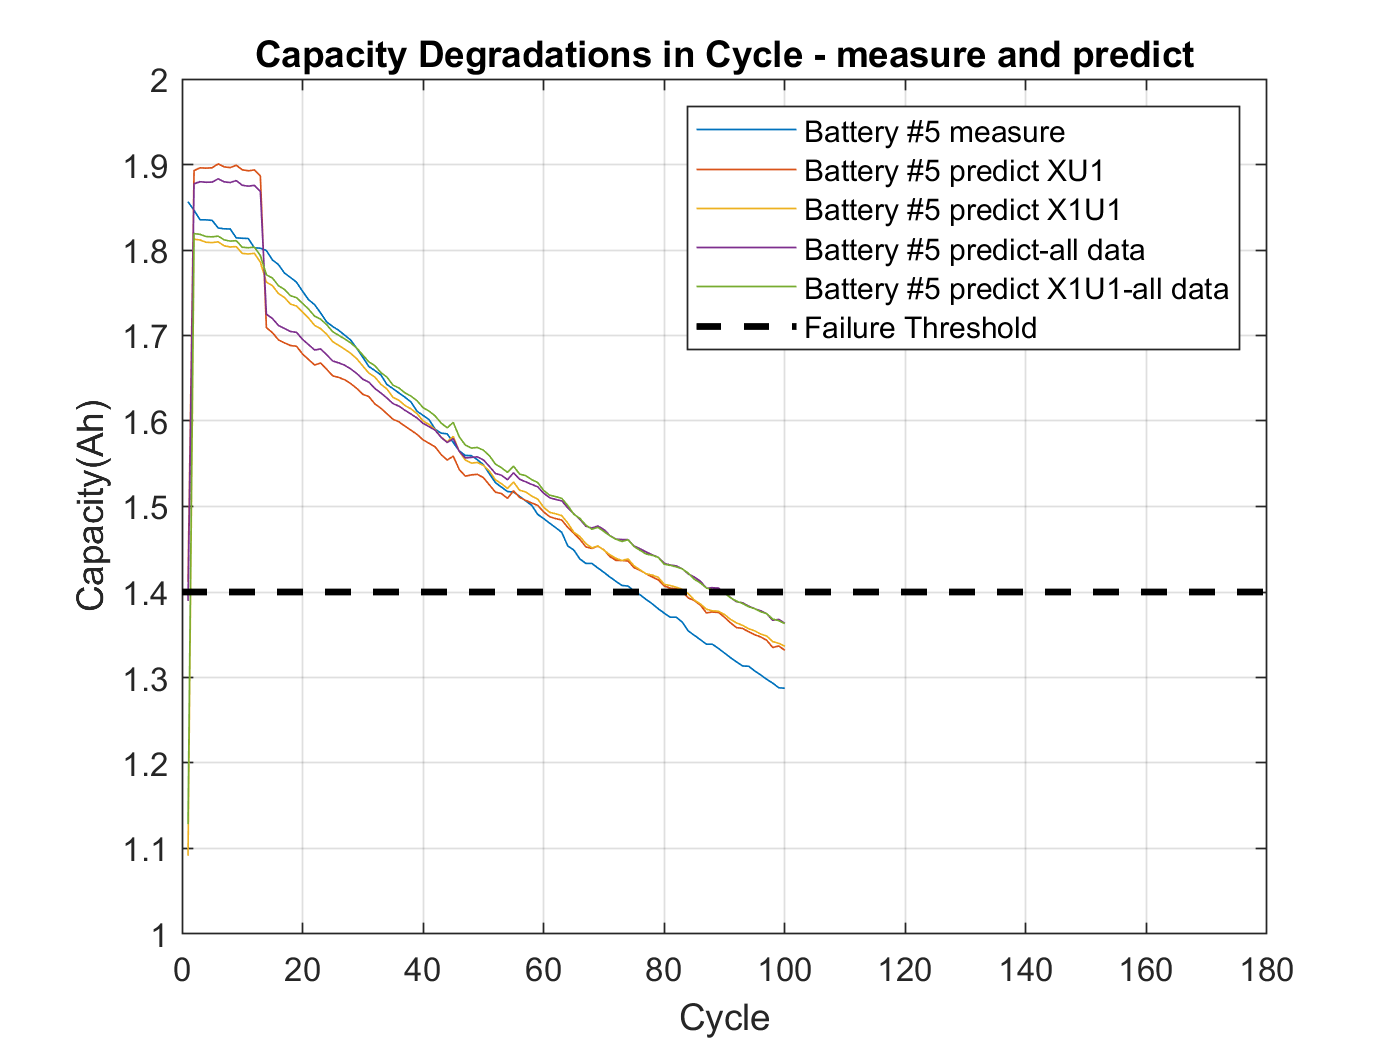

figure


%% plot - hat 
figure
plot(capacity05), hold on, plot(capacityHat05),plot(capacityX1U1Hat5),plot(capacityHat),plot(capacityX1U1Hat)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 measure', 'Battery #5 predict XU1', 'Battery #5 predict X1U1','Battery #5 predict-all data', 'Battery #5 predict X1U1-all data','Failure Threshold')
title('Capacity Degradations in Cycle - measure and predict')

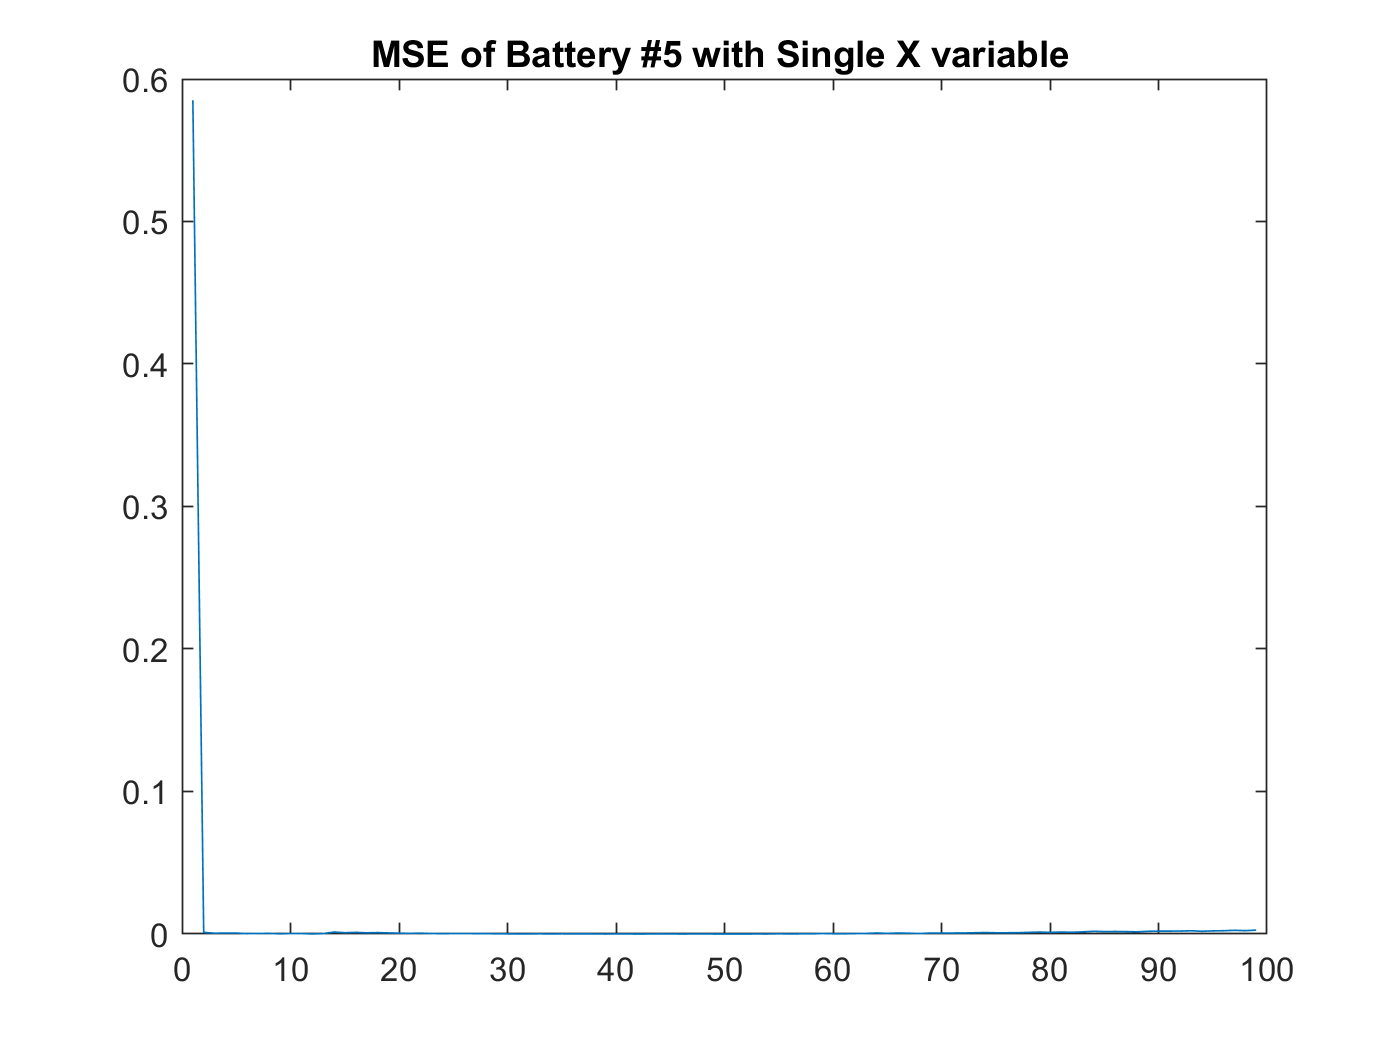


%%

% https://kr.mathworks.com/matlabcentral/answers/4064-rmse-root-mean-square-error
% https://kr.mathworks.com/matlabcentral/answers/234047-plot-mean-square-error

%%
% https://kr.mathworks.com/matlabcentral/answers/26944-plotting-rmse
% not works
%{
dt = 0.1;
k = length(capacity05);
capacityT5 = capacity05';
capacityX1U1HatT5 = capacityX1U1Hat5';
err(k)=sqrt(sum(capacityT5(1:k,1)-capacityX1U1HatT5(1:k,1))^2/k);
t(k) = dt*k;  %simulation time, where dt is time for one increment of loop
%outside of loop:
figure
plot(err,t)
title('RMSE of Battery #5 with Single X variable ')
%}


%%
N = length(capacity05);
for i = 1:N-1
    mse_var(i) = mean((capacity05(i)-capacityX1U1Hat5(i)).^2);
end
figure
plot(abs(mse_var));
title('MSE of Battery #5 with Single X variable ')


%% summary
% https://kr.mathworks.com/help/stats/linearmodel.html
anova(modelspecXU1_05,'summary')

ans = 3×5 table
                SumSq     DF     MeanSq        F         pValue  
                ______    __    _________    ______    __________

    Total       3.0512    99      0.03082                        
    Model       2.6464     2       1.3232    317.07    2.8477e-43
    Residual    0.4048    97    0.0041732                        


anova(mdlX1U1_05,'summary')

ans = 3×5 table
                 SumSq     DF     MeanSq        F        pValue  
                _______    __    _________    ______    _________

    Total        3.0512    99      0.03082                       
    Model        2.3956     1       2.3956    358.15    1.699e-34
    Residual    0.65551    98    0.0066889                       



modelspecXU1_05.MSE

ans = 0.0042

modelspecXU1_05.RMSE % 0.0131

ans = 0.0646

modelspecXU1_05.SSE

ans = 0.4048

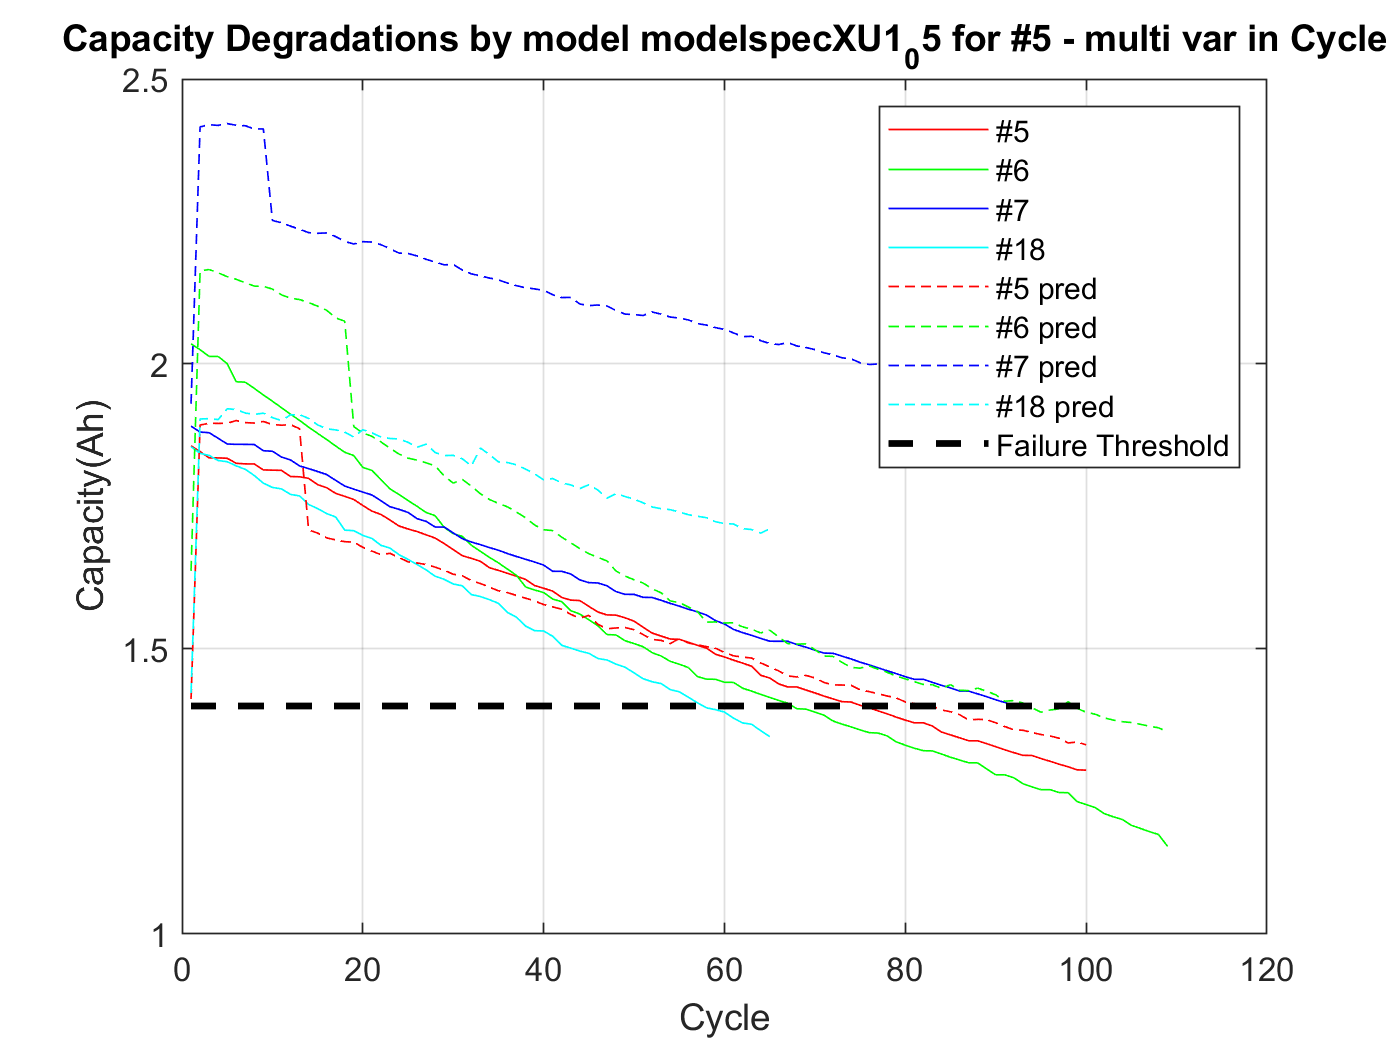

%% model modelspecXU1_05 from battery 5 - predict other battery
pred6_by_mdlXU1_05 = predict(modelspecXU1_05,regression_table_06(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}));
pred7_by_mdlXU1_05 = predict(modelspecXU1_05,regression_table_07(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}));
pred18_by_mdlXU1_05 = predict(modelspecXU1_05,regression_table_18(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}));

%% plot
cycle_number = length(capacity05);

figure
plot(capacity05,'r'), hold on, plot(capacity06,'g'), plot(capacity07,'b'), plot(capacity18,'c')
plot(capacityHat05,'r--'), hold on, plot(pred6_by_mdlXU1_05,'g--'), plot(pred7_by_mdlXU1_05,'b--'), plot(pred18_by_mdlXU1_05,'c--')
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('#5', '#6', '#7', '#18','#5 pred', '#6 pred', '#7 pred', '#18 pred','Failure Threshold')
title('Capacity Degradations by model modelspecXU1_05 for #5 - multi var in Cycle')

5+6, 5-6,6-5 

평가 5-6 <= modelspecXU1_05, modelspecXU1_06 ,modelspecXU1_05-6, modelspecXU1_06-5,mdlXU1 5,6 

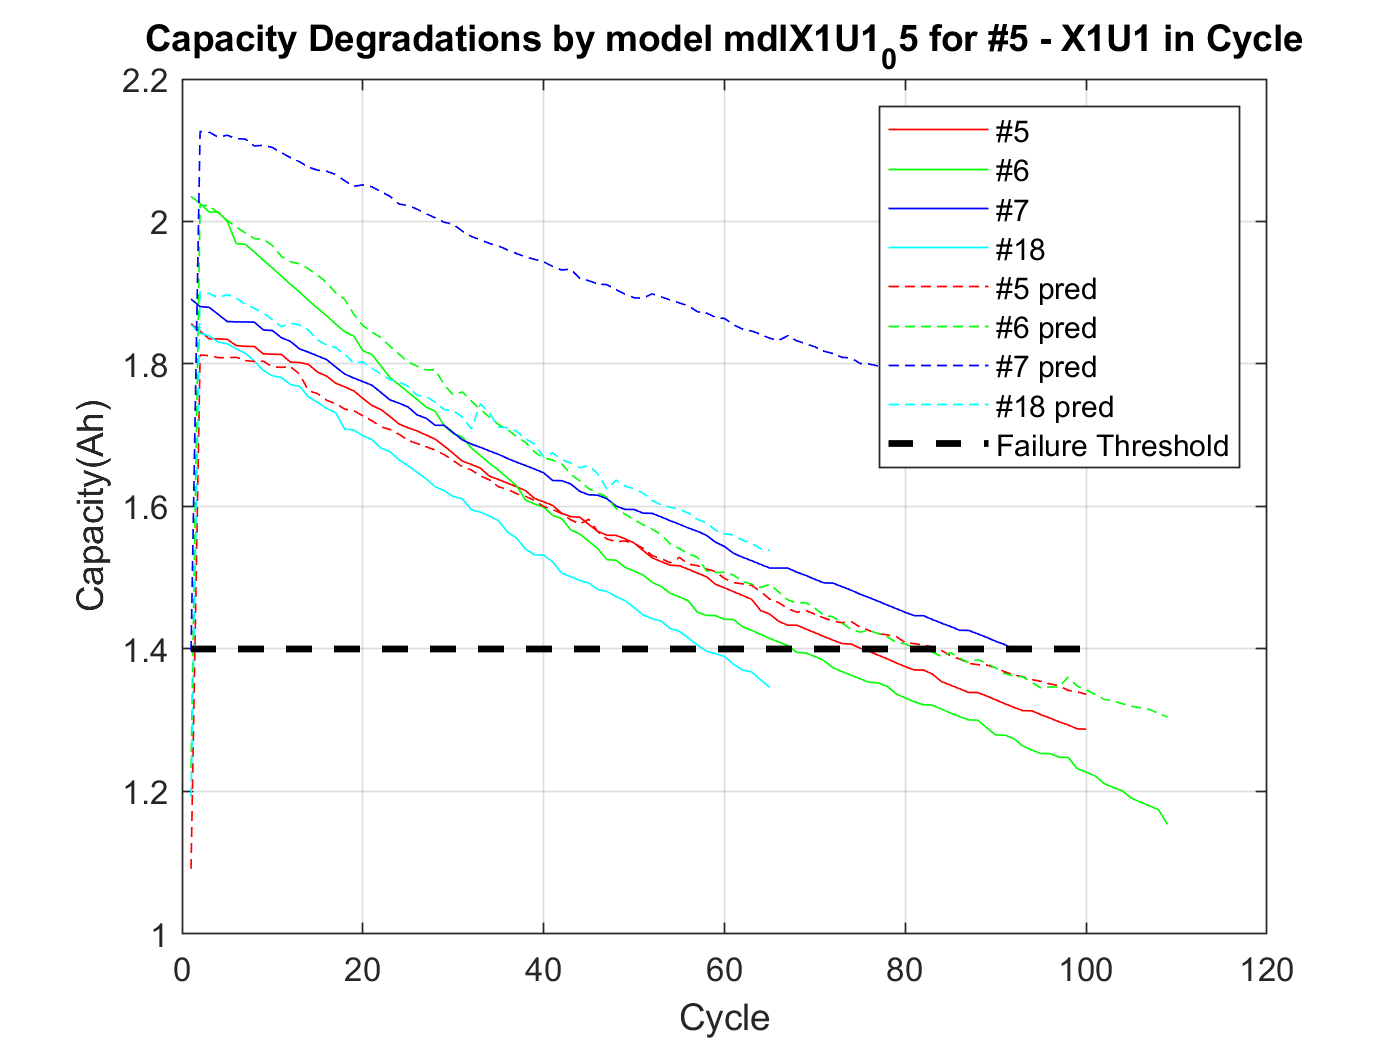

%% model from battery 5 - predict other battery
pred6_by_mdlX1U1_05 = predict(mdlX1U1_05,regression_table_06(:,{'cCcEndTimeSec','pattern_dVolt'}));
pred7_by_mdlX1U1_05 = predict(mdlX1U1_05,regression_table_07(:,{'cCcEndTimeSec','pattern_dVolt'}));
pred18_by_mdlX1U1_05 = predict(mdlX1U1_05,regression_table_18(:,{'cCcEndTimeSec','pattern_dVolt'}));

%% plot
cycle_number = length(capacity05);

figure
plot(capacity05,'r'), hold on, plot(capacity06,'g'), plot(capacity07,'b'), plot(capacity18,'c')
plot(capacityX1U1Hat5,'r--'), hold on, plot(pred6_by_mdlX1U1_05,'g--'), plot(pred7_by_mdlX1U1_05,'b--'), plot(pred18_by_mdlX1U1_05,'c--')
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('#5', '#6', '#7', '#18','#5 pred', '#6 pred', '#7 pred', '#18 pred','Failure Threshold')
title('Capacity Degradations by model mdlX1U1_05 for #5 - X1U1 in Cycle')




% 18 번 6번은 잘 적용이 안되고 특히 18번은 오류가 많다.
% 아무래도 cCcEndTimeSec 값이 해당 배터리에서 적용이 잘 안되는 것 같다.



% https://kr.mathworks.com/matlabcentral/answers/386493-rmse-between-two-variables
modelspecXU1_05.RMSE

ans = 0.0646

modelspecXU1_06.RMSE

ans = 0.0624

modelspecXU1_07.RMSE

ans = 0.0626

modelspecXU1_18.RMSE

ans = 0.0760


RMSE_5 = sqrt(mean(( capacity05 - capacityHat05 ).^2))

RMSE_5 = 0.0636

RMSE_6 = sqrt(mean(( capacity06 - capacityHat06 ).^2))

RMSE_6 = 0.0615

RMSE_7 = sqrt(mean(( capacity07 - capacityHat07 ).^2))

RMSE_7 = 0.0615

RMSE_18 = sqrt(mean(( capacity18 - capacityHat18 ).^2))

RMSE_18 = 0.0742


RMSE_5_by_mdlXU1_05 = sqrt(mean(( capacity05 - capacityHat05 ).^2))

RMSE_5_by_mdlXU1_05 = 0.0636

RMSE_6_by_mdlXU1_05 = sqrt(mean(( capacity06 - pred6_by_mdlXU1_05' ).^2))

RMSE_6_by_mdlXU1_05 = 0.1399

RMSE_7_by_mdlXU1_05 = sqrt(mean(( capacity07 - pred7_by_mdlXU1_05' ).^2))

RMSE_7_by_mdlXU1_05 = 0.4964

RMSE_18_by_mdlXU1_05 = sqrt(mean(( capacity18 - pred18_by_mdlXU1_05' ).^2))

RMSE_18_by_mdlXU1_05 = 0.2500


mdlX1U1_05.RMSE

ans = 0.0818

mdlX1U1_06.RMSE

ans = 0.0880

mdlX1U1_07.RMSE

ans = 0.0869

mdlX1U1_18.RMSE

ans = 0.1052

% https://kr.mathworks.com/matlabcentral/answers/286146-why-rmse-obtained-by-fitlm-in-matlab-does-not-match-with-rmse-calculated-in-excel
% As you can see, dividing by the degrees of freedom is what fitlm must be doing.
% sqrt(sum((y - lm.predict(x)).^2/100)) 
% sqrt(sum((y - lm.predict(x)).^2/100))  -> dividing by the degrees of freedom
RMSE_X1U1_5 = sqrt(mean(( capacity05 - capacityX1U1Hat5 ).^2))

RMSE_X1U1_5 = 0.0810

RMSE_X1U1_6 = sqrt(mean(( capacity06 - capacityX1U1Hat6 ).^2))

RMSE_X1U1_6 = 0.0872

RMSE_X1U1_7 = sqrt(mean(( capacity07 - capacityX1U1Hat7 ).^2))

RMSE_X1U1_7 = 0.0859

RMSE_X1U1_18 = sqrt(mean(( capacity18 - capacityX1U1Hat18 ).^2))

RMSE_X1U1_18 = 0.1036


RMSE_5_by_mdlX1U1_05 = sqrt(mean(( capacity05 - capacityX1U1Hat5 ).^2))

RMSE_5_by_mdlX1U1_05 = 0.0810

RMSE_6_by_mdlX1U1_05 = sqrt(mean(( capacity06 - pred6_by_mdlX1U1_05' ).^2))

RMSE_6_by_mdlX1U1_05 = 0.1071

RMSE_7_by_mdlX1U1_05 = sqrt(mean(( capacity07 - pred7_by_mdlX1U1_05' ).^2))

RMSE_7_by_mdlX1U1_05 = 0.3046

RMSE_18_by_mdlX1U1_05 = sqrt(mean(( capacity18 - pred18_by_mdlX1U1_05' ).^2))

RMSE_18_by_mdlX1U1_05 = 0.1572


%% ARIMA 
% https://www.kaggle.com/sumi25/understand-arima-and-tune-p-d-q
% https://machinelearningmastery.com/arima-for-time-series-forecasting-with-python/
